# Smart Cantilever Beam 1D Finite Element Model: Active control

Author: Febvre Maryne

Date: 04/2022 

Objective: This script observes the dynamic behavior of a cantilever beam using a finite element model (FEM). The beam has piezoelectric patches for sensing and actuation. Active control is applied on the piezoelectric transducers using classical control laws tunned according to the litterature.

clc 
clf
close all
clear all

Load model data computed from script : 'Smart_cantilever_beam_1D_FEM_livescript.mlx'

load('Datas/FEM_smart_beam.mat','Sys_sc','Sys_oc','Sys_rs')

Flag to save figures (set to 1 to save)

save_figure_var = 0; % 1 to save figure, 0 to not save

## Active control implementation

This section exposes the implementation of a feedback active control applied on the finite element smart structure. 

### System to control

The smart bean to control is defined as an open loop transferfunction of the system G(s):  

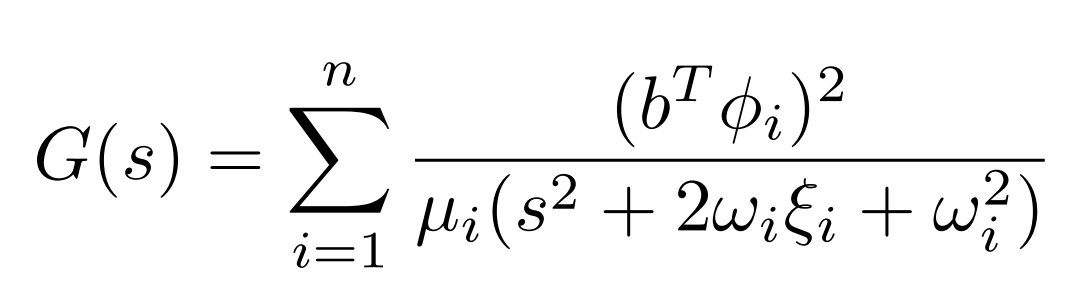

Where s is the Laplace variable, n is the number of modes, $b^{T\;} \phi_i$ is the modal amplitude at the transducer location, µi the modal mass, ωi is the natural frequencies of the system [rad.sec−1 ] and, ξ is the modal damping ratio. In the example case with the beam, the open-loop transfer function is taken between a virtual force actuator and a displacement sensor at node 6 (strong approximation with piezoelectric transducers used as sensors and actuators). Various feedback control laws C(s) are applied to the system to control the vibrations as shown on the following sheme, where r is the target signal (r = 0 for the example), e is the error, C(s) is the control law, ud is the disturbance signal, uc is the command signal, u is the input signal, y is the output signal. 

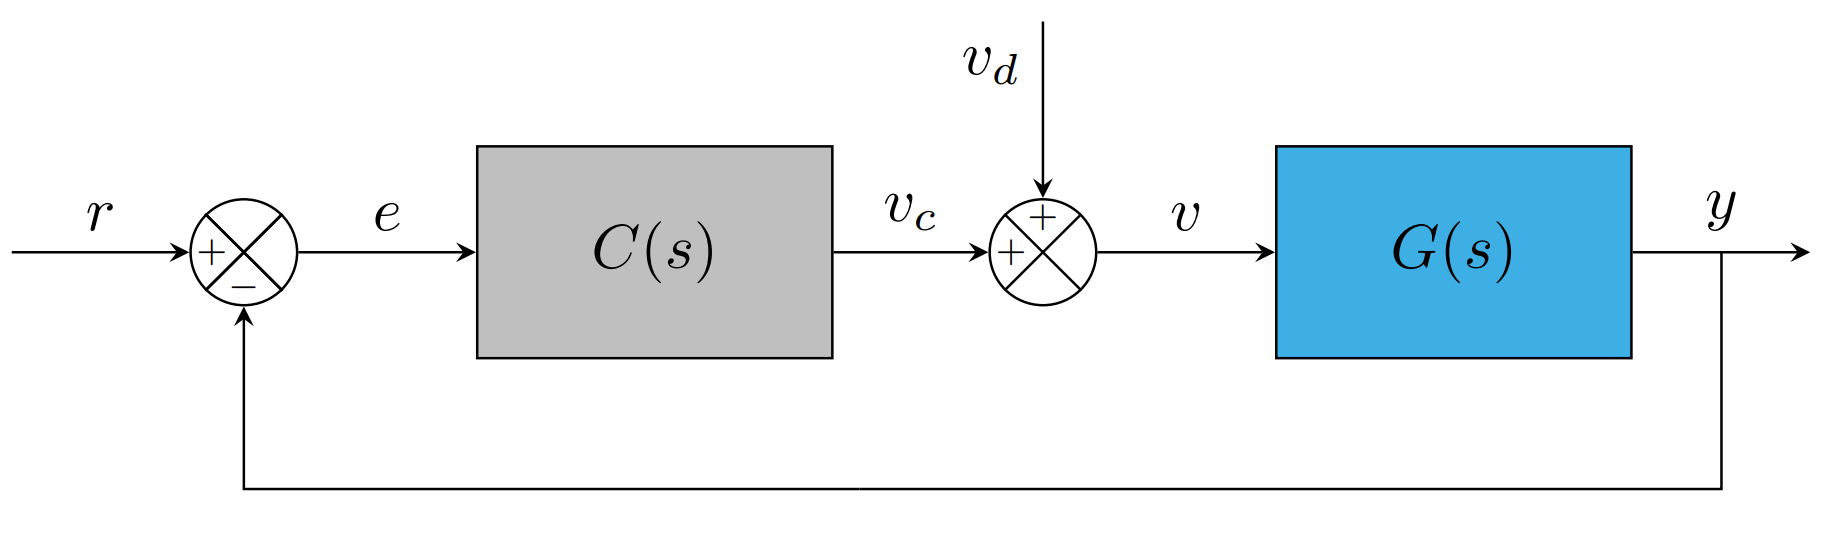

### Setup parameters for the feedback control

Define laplace variable:

s = tf('s');

#### Bode response

Create a figure for plotting the frequency response of the system

interval_plot = [1:0.1:8e4];  % Frequency interval for Bode plot

Input disturbance of the transfert function 

input_tf = 2; % input_tf = 2; Input Force Fu, Chose input_tf = 1; for Input q. 

Output measurement of the transfert function 

ouput_tf =12 ; % Output measurement w_6 displacement 

System definition

G=Sys_rs(ouput_tf,input_tf);

Figure parameters

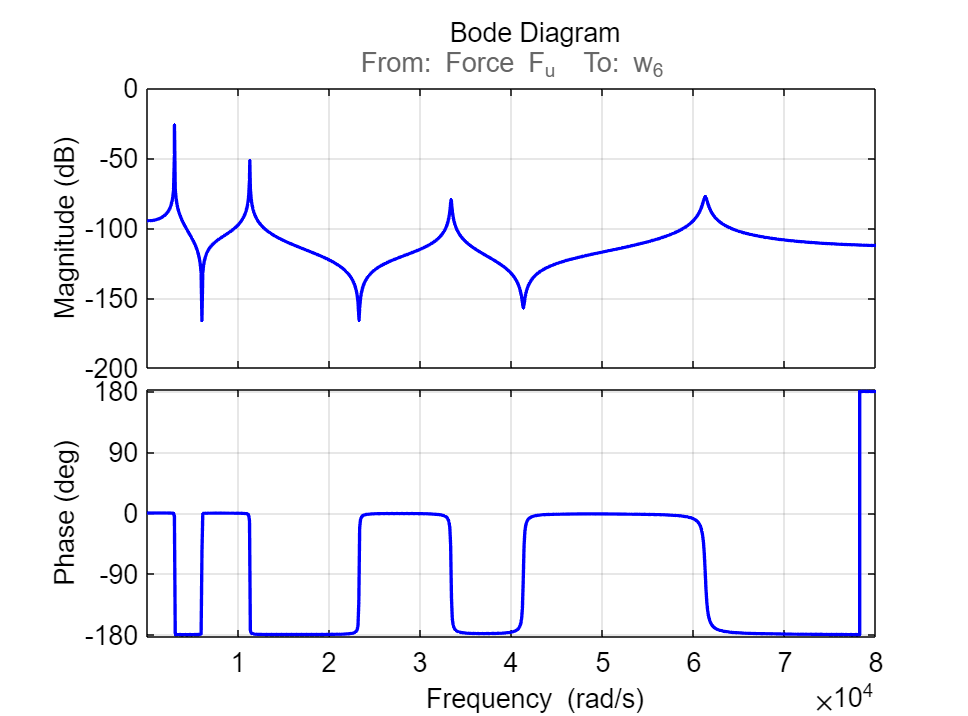

fig1 = figure;
g=bodeoptions;
g.FreqScale='Linear';
g.PhaseWrapping ='on';
g.Grid='on';
g.XLim={[1 8e4]};
fig1.Name = 'Bode plot';  % Name of the figure

bodeplot(G, 'b', interval_plot, g)
fontsize(fig1, 16, "points")
fig1.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

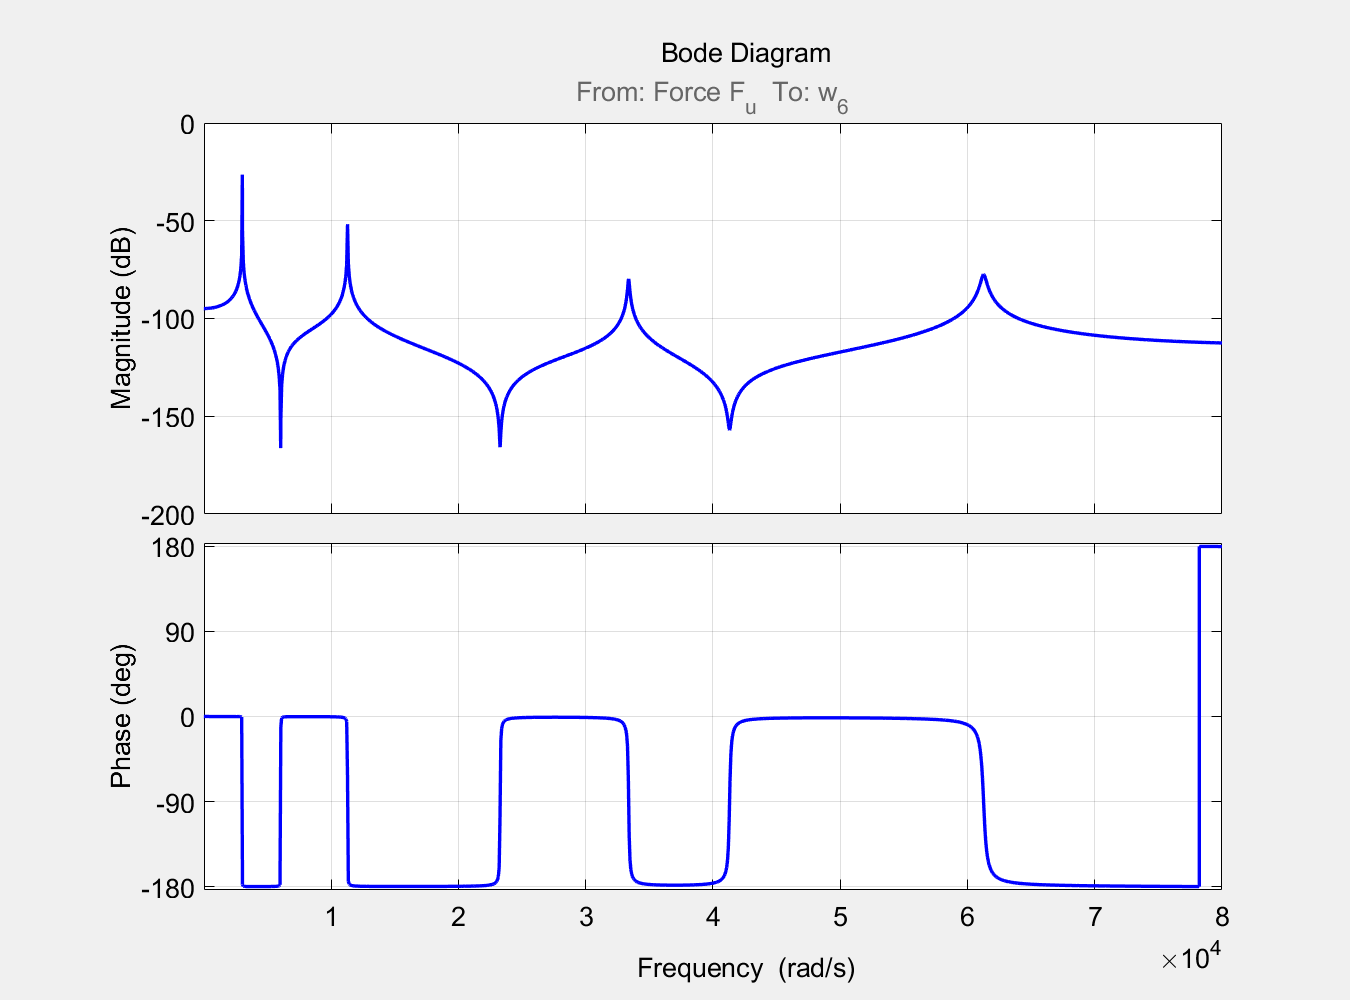

if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_off')
    save_fig_pdf('Figures/Bode_G_crtl_off')
end

#### Root Locus

Create a figure for the root locus, pole and zeros of the system G(s)

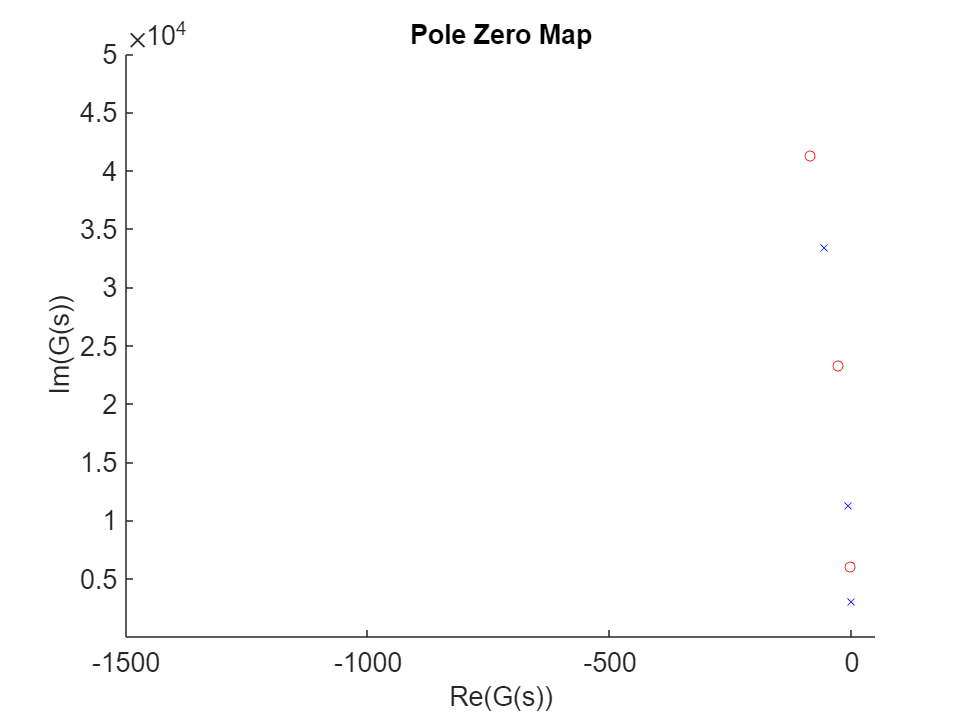

% Define Figure to plot the poles of the system
fig2 = figure;
fig2.Name = 'Pole Zero Map';
hold on;
scatter(real(pole(G)),imag(pole(G)),'x', 'b')
scatter(real(zero(G)),imag(zero(G)),'o', 'r')
xlim([-1500 50])
ylim([0.01 5e4])
xlabel('Re(G(s))')
ylabel('Im(G(s))')
title(fig2.Name)
hold off;

fontsize(fig2, 16, "points")
fig2.Position = [100 100 540*2 400*2];

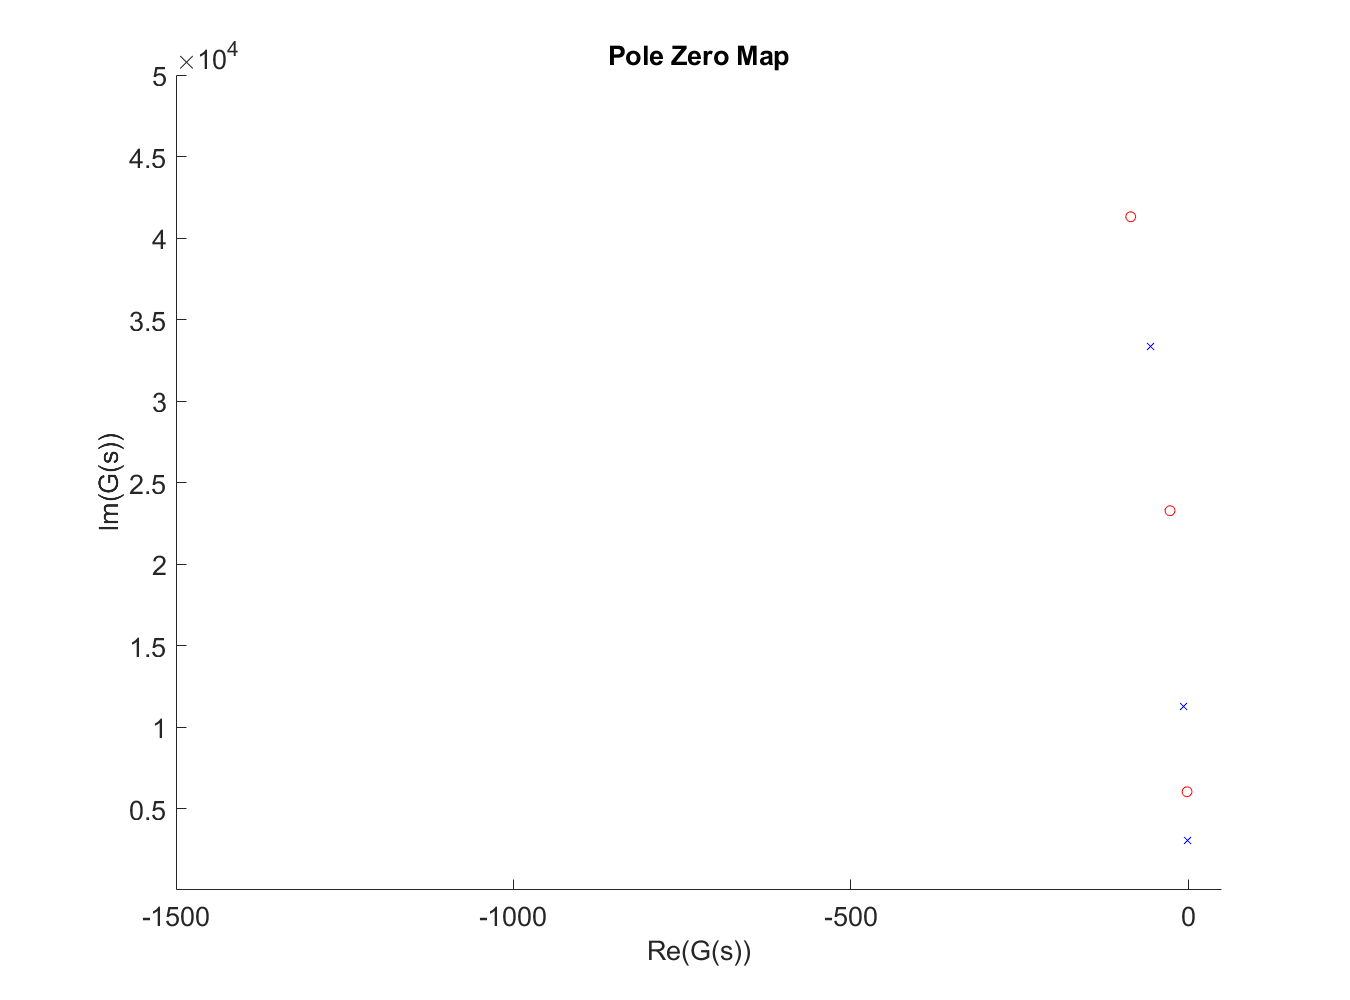

if save_figure_var == 1
savefig('Figures/Rlocus_G_crtl_off')
save_fig_pdf('Figures/Rlocus_G_crtl_off')
end

### Stability and Robustness criteria

To apply control on a system, it is necessary to ensure stability. Various criteria can be used to quantify it.

In this section, it is chosen to have a proportional feedback gain for the example, such as: $C\left(s\right)=40$

Crtl = 40

Crtl = 40

#### Complex Plane

The first stability criterion is based on the poles of the system. The system is stable if all poles of the transfer function have a negative real part Re(G(s)) < 0.

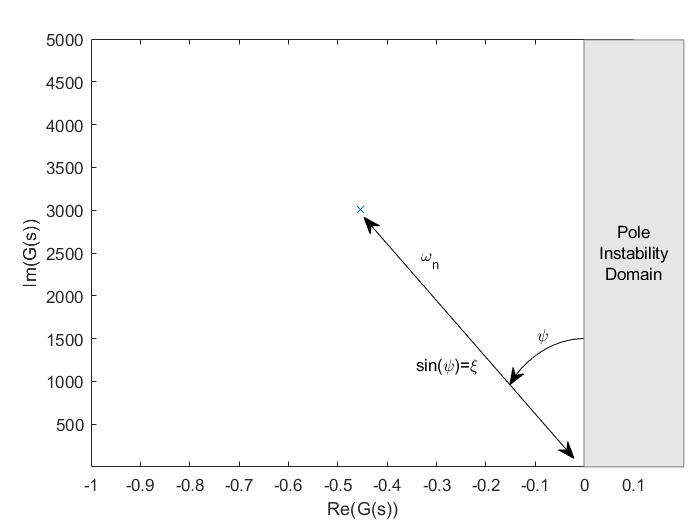

figure
plot(real(pole(Crtl*G)),imag(pole(Crtl*G)),'x')
hold on
plot(real(zero(Crtl*G)),imag(zero(Crtl*G)),'o')
xlim([-1 0.1])
ylim([0.1 0.5e4])
xlabel('Re(G(s))')
ylabel('Im(G(s))')

% Create arrow
annotation('arrow',[0.52 0.82],...
    [0.586 0.127]);
annotation('arrow',[0.82 0.52 ],...
    [ 0.127 0.586]);

% Create textbox
annotation('textbox',...
    [0.589 0.474 0.1 0.07],...
    'String','\omega_n',...
    'FitBoxToText','off',...
    'EdgeColor','none');


% Define the center and radii of the ellipse
centerX = 0; % X coordinate of the center
centerY = 0; % Y coordinate of the center
radiusX = 0.2; % Radius along the X-axis
radiusY = 1500; % Radius along the Y-axis

% Define the start and end angles of the arc (in degrees)
startAngle = 137.5;
endAngle = 90;

% Generate the points for the ellipse arc
theta = linspace(deg2rad(startAngle), deg2rad(endAngle), 100); % Convert degrees to radians
x = centerX + radiusX * cos(theta);
y = centerY + radiusY * sin(theta);

% Plot the ellipse arc
plot(x, y, 'k-'); % 'b-' specifies a blue line

% Create textbox
annotation('textbox',[0.583 0.265 0.099 0.07],...
    'String','sin(\psi)=\xi',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation('textbox',...
    [0.834375 0.110816287878788 0.142625 0.813189393939394],...
    'VerticalAlignment','middle',...
    'String','Pole Instability Domain',...
    'HorizontalAlignment','center',...
    'FitBoxToText','off',...
    'EdgeColor',[0.501960784313725 0.501960784313725 0.501960784313725],...
    'BackgroundColor',[0.901960784313726 0.901960784313726 0.901960784313726]);

% Create arrow
annotation('arrow',[0.736458333333333 0.728125],...
    [0.285037878787879 0.267045454545455]);

% Create textbox
annotation('textbox',...
    [0.754717261904761 0.355211038961039 0.0166041666666666 0.0362499999999999],...
    'String','\psi',...
    'FitBoxToText','off',...
    'EdgeColor','none');

Comment: The position of the pole is related to the damping through the imaginary axis angle ψ, such as sin(ψ) = ξ. The more negative the real part of the pole is, the more damped the system is at the corresponding frequency. With a positive real part of the pole, the damping would be negative (ξ < 0) and the system response will be amplified at each time step, leading to divergence, called system instability. A limit case occurs when at least one of the poles is zero. The system is not damped at this frequency and gives an oscillatory response.

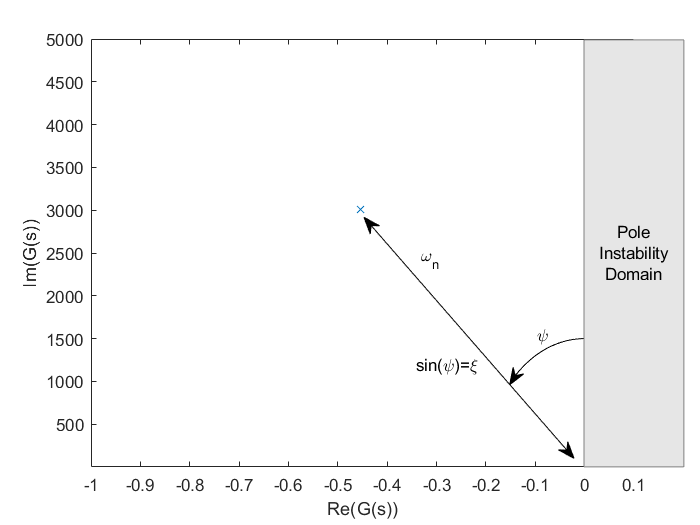

if save_figure_var == 1
savefig('Figures/PZ_damping_demo')
save_fig_pdf('Figures/PZ_damping_demo')
end

#### Nyquist diagram

The second stability criterion was discovered by Nyquist in 1932 [1]: A closed-loop system is stable if and only if the Nyquist plot, described by increasing omega, surrounds the point (-1,0), the number of positive real poles of the function 1 + C(s)G(s).

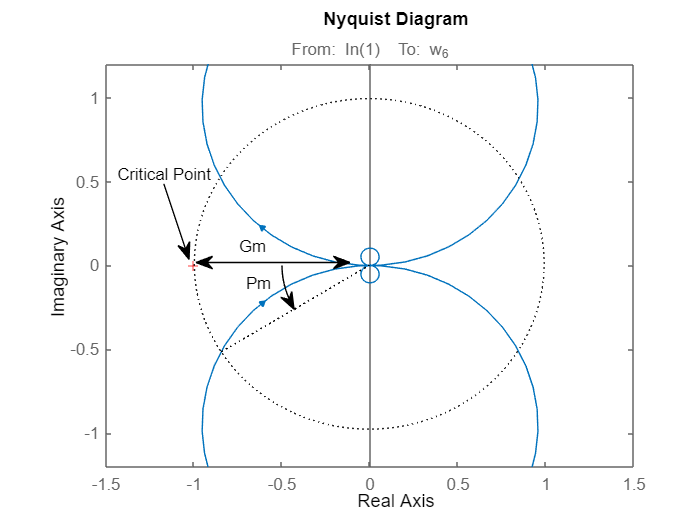

figure
nyquist(G*Crtl)
xlim([-1.5 1.5])
ylim([-1.2 1.2])
annotation('arrow', [0.28, 0.5], [0.5, 0.5]);
annotation('arrow', [0.5, 0.28], [0.5, 0.5]);

% Create textbox
% Create textbox
annotation('textbox',...
    [0.33 0.49 0.099 0.07],...
    'String','Gm',...
    'FitBoxToText','off',...
    'EdgeColor','none');


% Create textarrow
annotation('textarrow',[0.234 0.270],...
    [0.65 0.506],'String','Critical Point');

% Create ellipse
annotation('ellipse',...
    [0.2775 0.1824 0.50 0.63],...
    'Color',[0.149 0.149 0.149],...
    'LineStyle',':');
% Create line
annotation('line',[0.528 0.3157],...
    [0.495 0.3295],'LineStyle',':');

% Define the center and radii of the ellipse
centerX = 0; % X coordinate of the center
centerY = 0; % Y coordinate of the center
radiusX = 0.5; % Radius along the X-axis
radiusY = 0.5; % Radius along the Y-axis

% Define the start and end angles of the arc (in degrees)
startAngle = 180;
endAngle = 212;

% Generate the points for the ellipse arc
theta = linspace(deg2rad(startAngle), deg2rad(endAngle), 100); % Convert degrees to radians
x = centerX + radiusX * cos(theta);
y = centerY + radiusY * sin(theta);

% Plot the ellipse arc
hold on
plot(x, y, 'k-'); % 'b-' specifies a blue line

% Create arrow
annotation('arrow',[0.415 0.42],...
    [0.4237 0.411]);

annotation('textbox',...
    [0.34 0.42 0.099 0.07],...
    'String','Pm',...
    'FitBoxToText','off',...
    'EdgeColor','none');

Comment: The point (-1,0) is called the critical point. In most cases, the transfer loop does not have poles with a positive real part, so the criterion is simplified and called the Bode criterion: A linear closed-loop system is stable if and only if the critical point lies to the left of the Nyquist plot

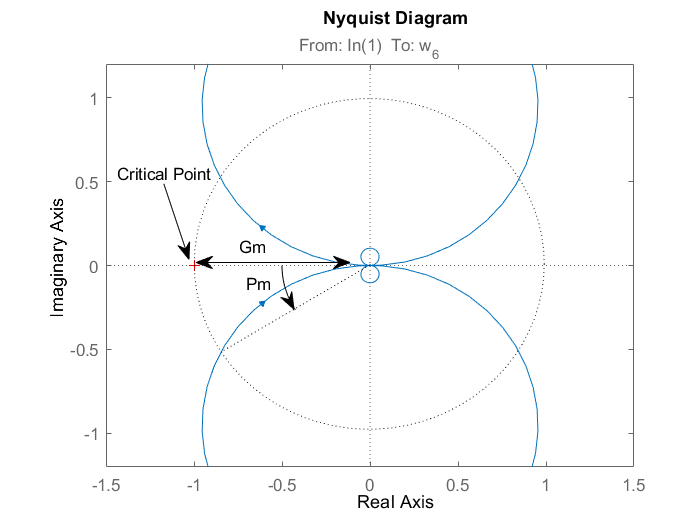

if save_figure_var == 1
    savefig('Figures/Nyquist_stability_40xG_demo')
    save_fig_pdf('Figures/Nyquist_stability_40xG_demo')
end

#### Bode criterion: Gain and Phase Margin

These criteria allow to introduce the concept of system robustness through the stability bounds. The phase margin Pm defines the amount of phase that can be added to the transfer loop before the system destabilizes, such as : 

where ω ∗ is the pulsation such as : |C(jω∗ )G(jω∗ )| = 1. 

The gain margin corresponds to the amount of gain that can be added to the transfert loop before the system destabilizes, such as : 

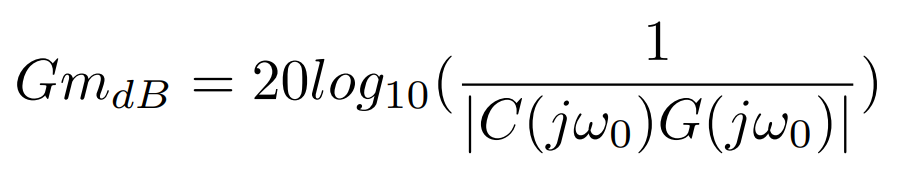

Where ω0 is the pulsation in [rad.s−1 ] where the Nyquist plot intersected the negative real axis. 

Both margins can be read from the Bode plot:

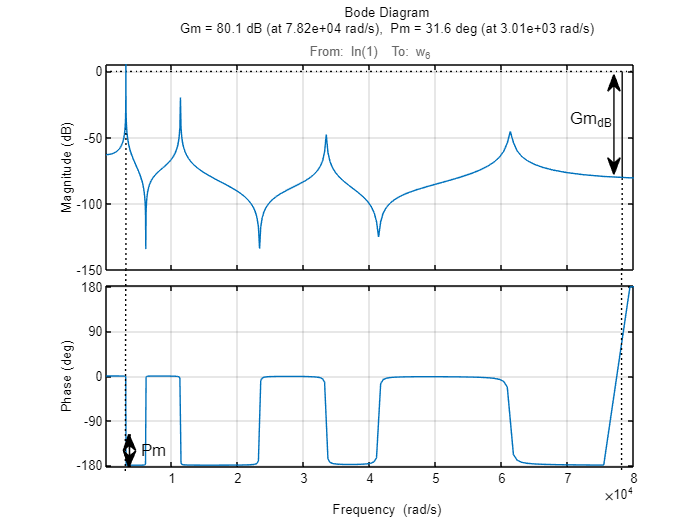

g.XLim={[1 8e4]};
figure
margin(G*Crtl,g)
% Create arrow
annotation('arrow',[0.877 0.877],...
    [0.858 0.668]);
annotation('arrow',[0.877 0.877],...
    [0.668 0.858]);

% Create textbox
annotation('textbox',...
    [0.80 0.729 0.064 0.073],...
    'String',{'Gm_{dB}'},...
    'FitBoxToText','off',...
    'EdgeColor','none');
% Create textbox
annotation('textbox',...
    [0.19 0.146 0.022 0.026],...
    'String','Pm',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create arrow
annotation('arrow',[0.186 0.184],...
    [0.11 0.173]);
% Create arrow
annotation('arrow',[0.186 0.184],...
    [0.173 0.11]);

% Create line
annotation('line',[0.1797 0.179],...
    [0.487 0.1],'LineStyle',':');

% Create line
annotation('line',[0.888 0.888],...
    [0.489 0.1],'LineStyle',':');

Comment: The phase margin Pm is the difference between the phase at the frequency where the transfer function module is zero and the horizontal asymptote at -180(deg). The gain margin GmdB is the difference between the module of the transfer function at the frequency where the phase is −180(deg) and the horizontal asymptote at 0dB. In practice, reasonable margins are the gain margin GmdB = 6dB and the phase margin Pm = 45 deg, allowing a trade-off between control efficiency and system stability.

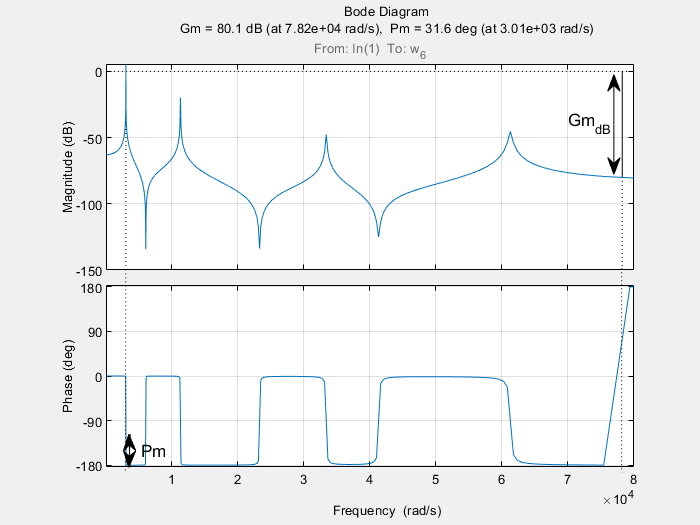

if save_figure_var == 1
savefig('Figures/Margin_demo_40xG_demo')
save_fig_pdf('Figures/Margin_demo_40xG_demo')
end

#### Nichols Black diagram

Using the Nichols plot makes it easy to read the stability margins.

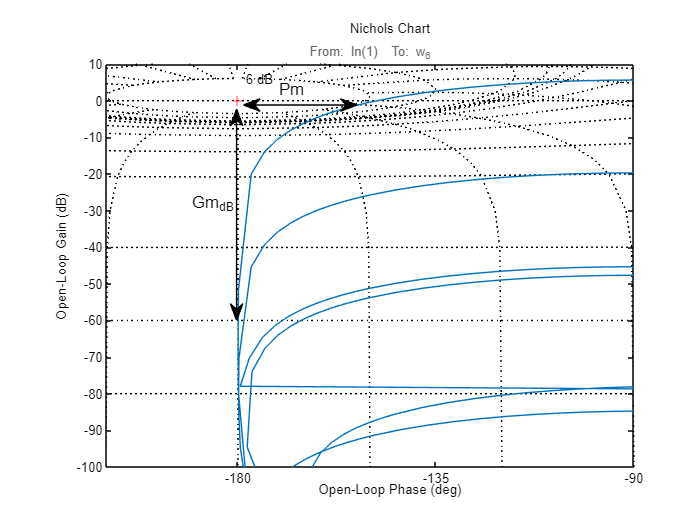

plotoptions = nicholsoptions;
plotoptions.Grid = 'on';
plotoptions.PhaseWrapping ='on';
plotoptions.XLim=[-210,-90];
plotoptions.YLim=[-100,10];

figure
nicholsplot(G*Crtl,plotoptions)

% Create arrow
annotation('arrow',[0.51 0.3479],...
    [0.8 0.80]);
annotation('arrow',[0.3479 0.51],...
    [0.8 0.80]);
% Create arrow
annotation('arrow',[0.338 0.338],...
    [0.792 0.39]);
annotation('arrow',[0.338 0.338],...
    [0.39 0.792]);

% Create textbox
annotation('textbox',...
    [0.259 0.608 0.029 0.033],...
    'String','Gm_{dB}',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation('textbox',...
    [0.386 0.831 0.0229 0.0284],...
    'String',{'Pm'},...
    'FitBoxToText','off',...
    'EdgeColor','none');

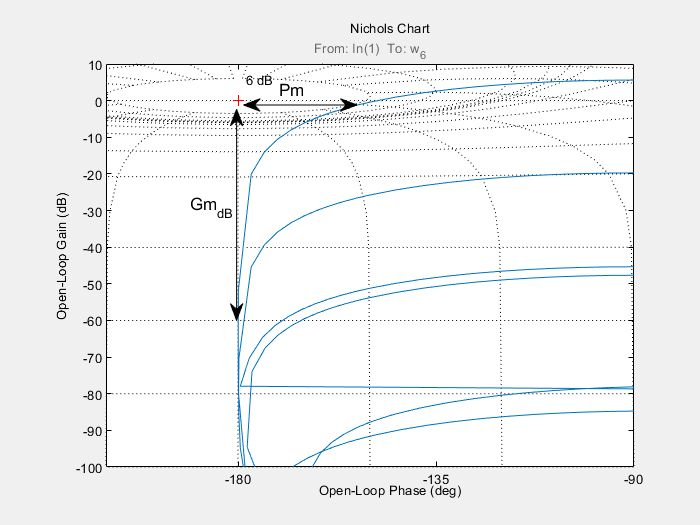

if save_figure_var == 1
savefig('Figures/Nichols_stability_40xG_demo')
save_fig_pdf('Figures/Nichols_stability_40xG_demo')
end

## Classical control laws implementation

Define system control inputs and outputs: piezoelectric transducers 

feedin = 1;  % Moment applied 
feedout = 1;  % Output is the displacement

#### Bode response

Create a figure for plotting the frequency response of the system

interval_plot = [1:0.1:8e4];  % Frequency interval for Bode plot

Input of the transfert function (only for visualization)

input_tf = 2; % input_tf = 2; Input Force Fu, Chose input_tf = 1; for Input q. 

Output of the transfert function (only for visualization)

ouput_tf =12 ; % Output measurement w_6 displacement 

### Proportional Integrator Derivative (PID) Feedback :

As described in Borase works [2], the PID controller, widely used in industrial applications, is easy to implement on systems with a simple formulation, such as :

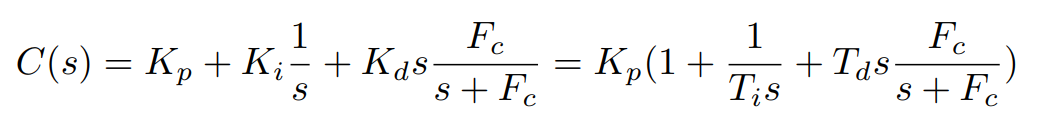

Where Kp is the proportional gain, Ki = Kp Ti is the integrator gain, Kd = KpTd is the derivative gain and Fc is the derivative filter frequency.

The most famous method for tuning a PID controller was introduced by Ziglers and Nichols [3] in 1942. This method is applied to the example in the following lines. 

#### Proportional (P) Feedback:

The proportional contributes to the control by adding a gain for error e through the closed loop and by modifying the static gain of the system as the ”sensitivity”. 

Kpu=4.058085*10^5;
Kp_ZN=Kpu/2

Kp_ZN = 2.0290e+05

Kp=[10.^4 Kpu Kp_ZN];
Kp_legend=["Kp = " "Kp = " "Kp = Ku = "  "Kp = 0.5 Ku = "]

Kp_legend = 1×4 string array
    "Kp = "    "Kp = "    "Kp = Ku = "    "Kp = 0.5 Ku = "


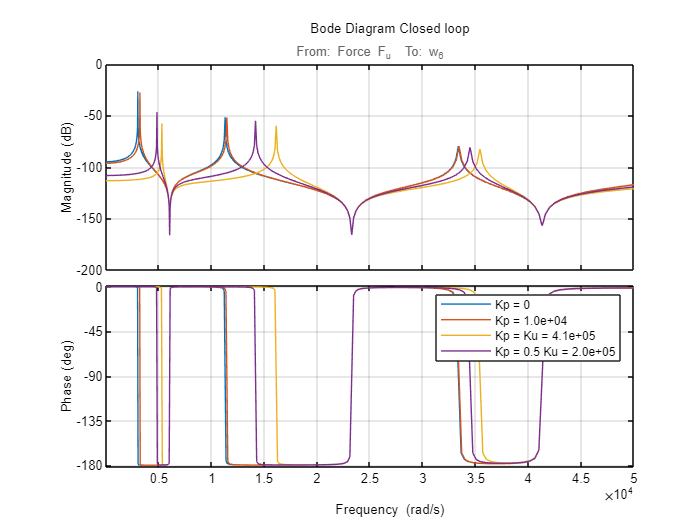

bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};
figure
bodeplot(G,bopt)
hold on
legend_P(1)="Kp = "+0 + " ";
for i=1:length(Kp)
G_fb_P(i)=feedback(G,Kp(i),feedin,feedout);
bodeplot(G_fb_P(i),bopt)
legend_P(i+1)=Kp_legend(i+1)+num2str(Kp(i), '%.1e')+ " ";
end
legend(legend_P)
title({'Bode Diagram Closed loop'},...
    'HitTest','off',...
    'Units','pixels',...
    'HorizontalAlignment','center',...
    'FontSize',8);

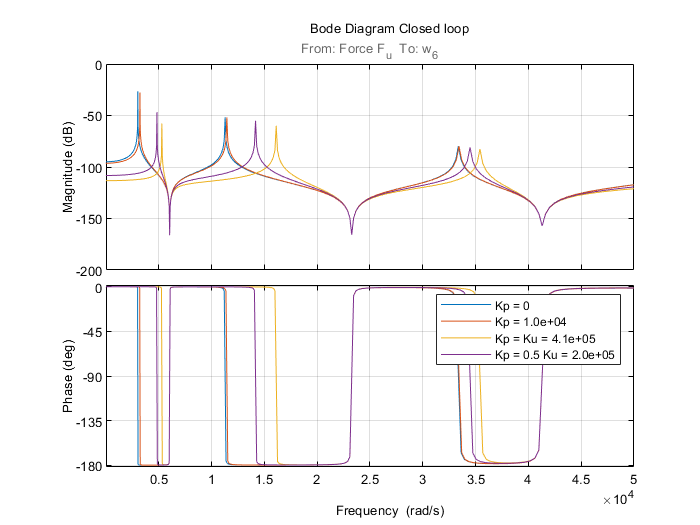

if save_figure_var == 1
savefig('Figures/Bode_G_crtl_P_var')
save_fig_pdf('Figures/Bode_G_crtl_P_var')
end

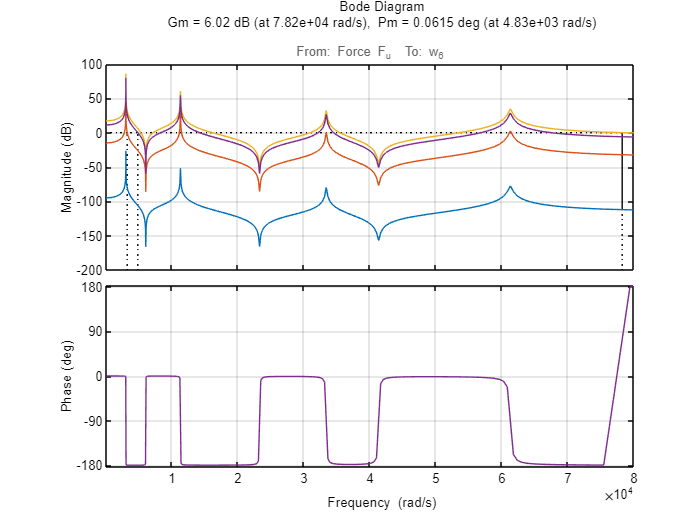

text_margin = "Gm = 3.2e+01dB  (at 7.8e+04rad/s),  Pm = 0.13894deg (at 3.2e+03 rad/s)"

text_margin = 2×1 string array
    "Gm = 3.2e+01dB  (at 7.8e+04rad/s),  Pm = 0.13894deg (at 3.2e+03 rad/s)"
    "Gm = 1.5e-05dB  (at 7.8e+04rad/s),  Pm = -0.0002291deg (at 7.8e+04 rad/s)"


text_margin = 3×1 string array
    "Gm = 3.2e+01dB  (at 7.8e+04rad/s),  Pm = 0.13894deg (at 3.2e+03 rad/s)"
    "Gm = 1.5e-05dB  (at 7.8e+04rad/s),  Pm = -0.0002291deg (at 7.8e+04 rad/s)"
    "Gm = 6.0e+00dB  (at 7.8e+04rad/s),  Pm = 0.061509deg (at 4.8e+03 rad/s)"



default_color=[0 0.4470 0.7410 ; ...
               0.8500 0.3250 0.0980 ;...
               0.9290 0.6940 0.1250; ...
               0.4940 0.1840 0.5560];

bopt.XLim={[1 8e4]};
figure
margin(G)
hold on
legend_P(1)="Kp = "+0 + " ";
for i=1:length(Kp)
margin(G*Kp(i),bopt)
[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*Kp(i));
legend_P(i+1)=Kp_legend(i+1)+num2str(Kp(i), '%.1e')+ " ";
text_margin(i,:)=("Gm = "+ num2str(20*log10(Gm1(i)), '%.1e') + "dB  (at "+ num2str(Wcg1(i), '%.1e') +"rad/s),  Pm = "+ num2str(Pm1(i)) + "deg (at "+ num2str(Wcp1(i), '%.1e') +" rad/s)")
end

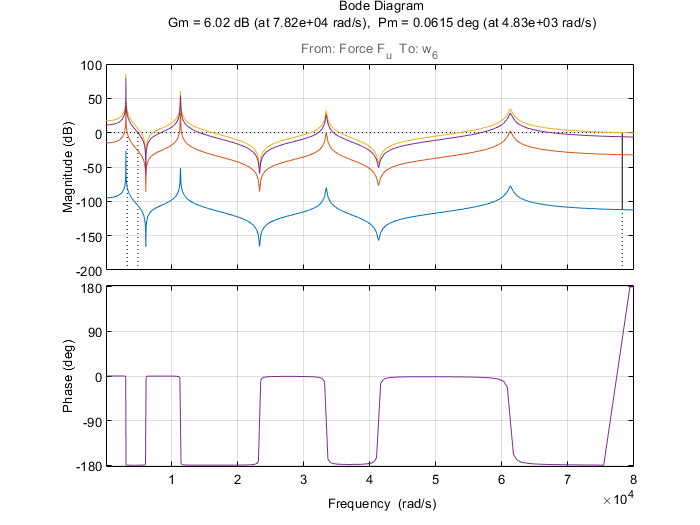

if save_figure_var == 1
savefig('Figures/Bode_G_crtl_P_var_margin')
save_fig_pdf('Figures/Bode_G_crtl_P_var_margin')
end

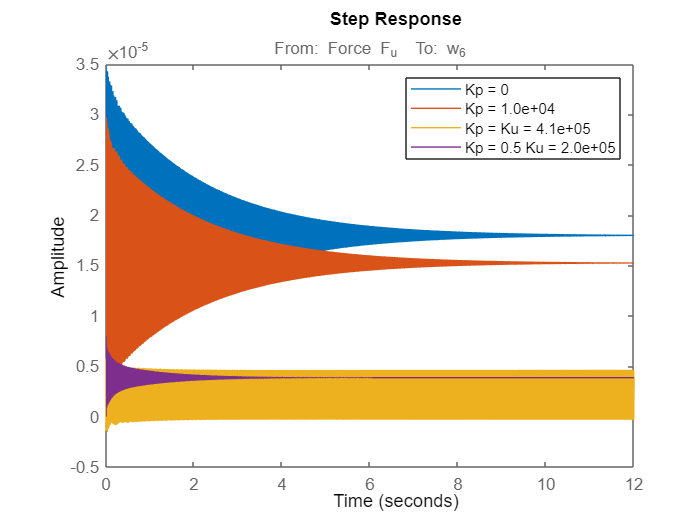

figure
step(G)
[~,time]=step(G);
for i=1:length(Kp)
hold on
step(G_fb_P(i))
end
legend(legend_P)

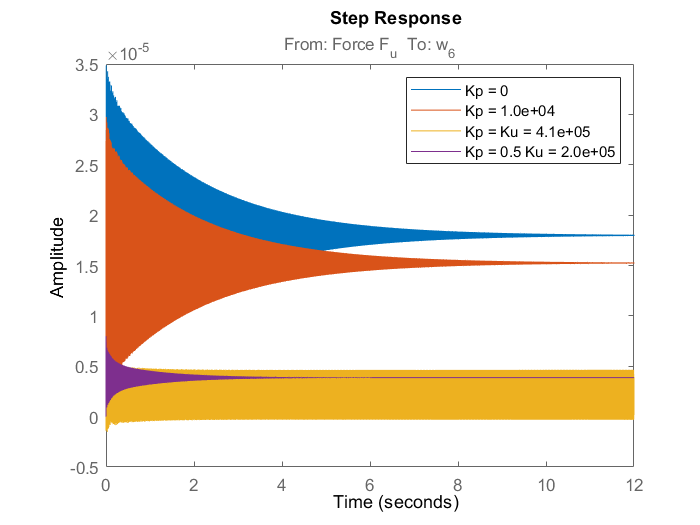

%xlim([0 12])
if save_figure_var == 1
savefig('Figures/Step_G_crtl_P_var');
save_fig_pdf('Figures/Step_G_crtl_P_var');
end

figure
impulseplot(G)
[~,time]=impulse(G)

time =          0
    0.0004
    0.0008
    0.0012
    0.0016
    0.0020
    0.0024
    0.0028
    0.0032
    0.0037


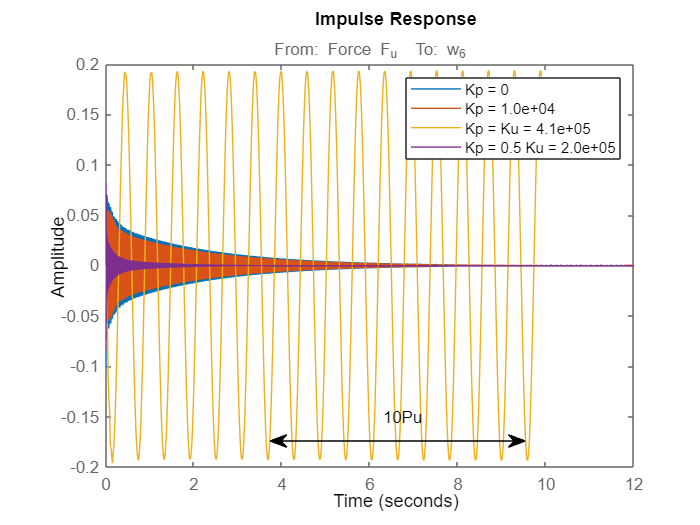

for i=[1 2 3]%1:length(Kp)
hold on
if i==2
impulse(G_fb_P(i),time(1:40:end));
else
impulse(G_fb_P(i));
end
end
legend(legend_P)
xlim([0 12])
%uistack(h{3}, 'bottom');
% Create arrow
annotation('arrow',[0.386 0.75],...
    [0.160 0.160]);
annotation('arrow',[0.75 0.386],...
    [0.160 0.160]);

% Create textbox
annotation('textbox',...
    [0.535714285714285 0.174285714285714 0.0569999999999999 0.0600000000000001],...
    'String',{'10Pu'},...
    'FitBoxToText','off',...
    'EdgeColor','none');

Comment: System oscillation can increase because the system time response is not reduced when the controller gain is above the so-called ”ultimate sensitivity” Kpu where Gm = 0. Ziegler and Nichols recommend finding this ultimate sensitivity gain and taking half the value to tune an efficient proportional gain Kpe = 0.5Ku. This chosen value is a compromise between stability and amplitude ratio.

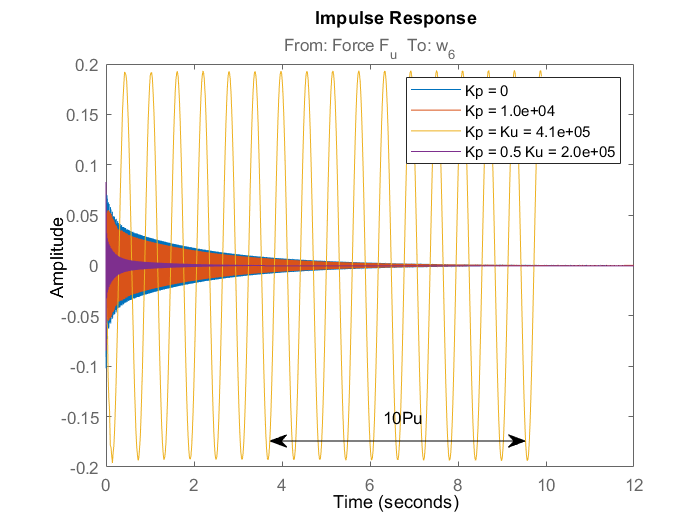

if save_figure_var == 1
savefig('Figures/Impulse_G_crtl_P_var');
save_fig_pdf('Figures/Impulse_G_crtl_P_var');
end

#### Proportional Integrator (PI) Feedback :

The integrator reduces the offset of the error e over time as an ”automatic reset”. It is defined by Ti = 1/Ki , called the integral action time. To increase the accuracy, Ti must be increased so that the integration order is higher than the static error order. It must be combined with other controllers because an integral action alone can lead to system instability by adding a −π/2 phase. The Ziegler-Nichols tuning method uses the period of the oscillation Pu generated at the ultimate sensitivity Ku, such as Ki = 0.54Ku/Pu.

Pu=0.6

Pu = 0.6000

Kp=[10.^4 0.45*Kpu]

Kp = 1.0e+05 *

    0.1000    1.8261


Ki=[1e4 1.2*0.45*Kpu/Pu]

Ki = 1.0e+05 *

    0.1000    3.6523



bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};

Kp_legend=["Kp = " "Kp = "  "Kp = 0.45Ku = "]

Kp_legend = 1×3 string array
    "Kp = "    "Kp = "    "Kp = 0.45Ku = "


Ki_legend=["Ki = " "Ki = " "Ki = 0.54Ku/P_u = "]

Ki_legend = 1×3 string array
    "Ki = "    "Ki = "    "Ki = 0.54Ku/P_u = "


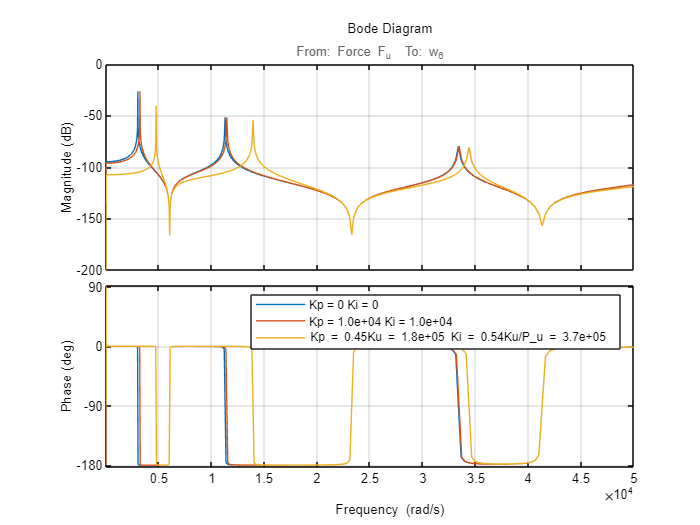


figure
bodeplot(G,bopt)
legend_I(1)=legend_P(1)+"Ki = "+num2str(0)+ " ";
for i=1:length(Ki)
G_fb_I(i)=feedback(G,(Kp(i)+Ki(i)/s),1,1);
hold on
bodeplot(G_fb_I(i),bopt)
legend_P(i+1)=Kp_legend(i+1)+num2str(Kp(i), '%.1e')+ " ";
legend_I(i+1)=legend_P(i+1)+Ki_legend(i+1)+num2str(Ki(i), '%.1e')+ " ";
end
legend(legend_I)

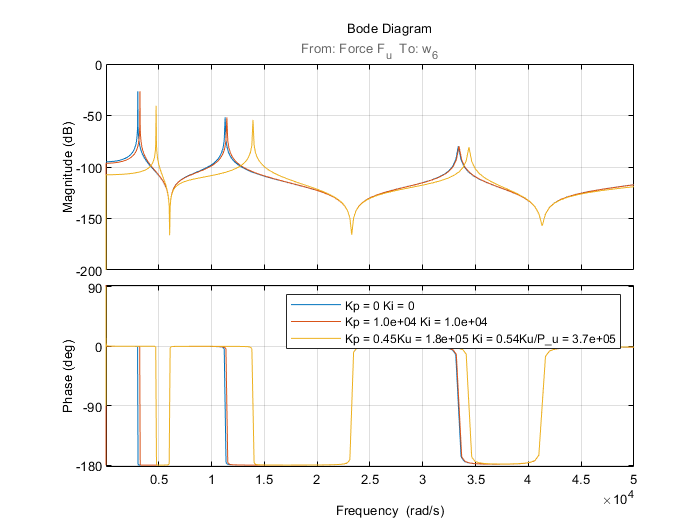

if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_I_var')
save_fig_pdf('Figures/Bode_G_crtl_I_var')
end

bopt.XLim={[1 8e4]};
figure
margin(G)
hold on
%legend_I(1)="Ki = "+ 0 + " ";
for i=1:length(Ki)
margin(G*(Kp(i)+Ki(i)/s),bopt)
[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*(Kp(i)+Ki(i)/s));
%legend_I(i+1)=Ki_legend(i+1)+num2str(Ki(i), '%.1e')+ " ";
%text_margin(i,:)=
("Gm = "+ num2str(20*log10(Gm1(i)), '%.1e') + "dB  (at "+ num2str(Wcg1(i), '%.1e') +"rad/s),  Pm = "+ num2str(Pm1(i)) + "deg (at "+ num2str(Wcp1(i), '%.1e') +" rad/s)")
end

ans = "Gm = 3.2e+01dB  (at 7.8e+04rad/s),  Pm = 0.12113deg (at 3.2e+03 rad/s)"

ans = "Gm = 6.9e+00dB  (at 7.8e+04rad/s),  Pm = 0.033383deg (at 4.7e+03 rad/s)"

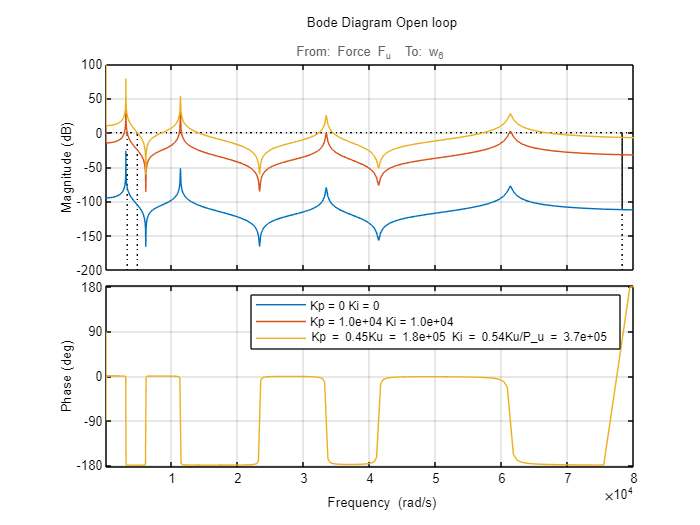


legend(legend_I)
% Create title
title({'Bode Diagram Open loop'},...
    'HitTest','off',...
    'Units','pixels',...
    'HorizontalAlignment','center',...
    'FontSize',8);

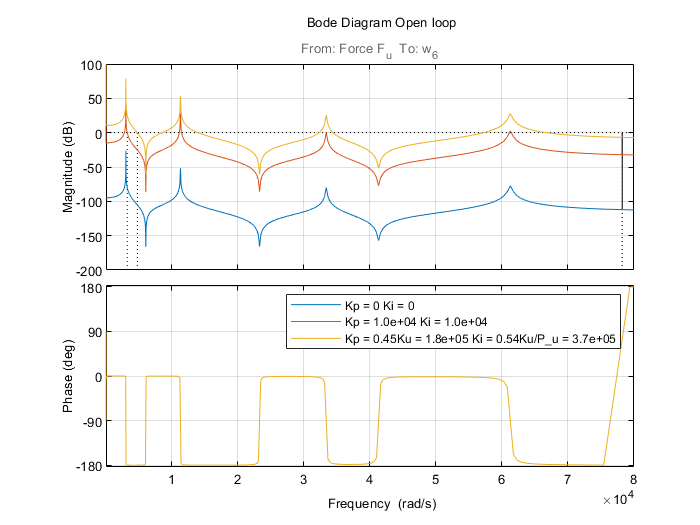

if save_figure_var == 1
savefig('Figures/Bode_G_crtl_I_var_margin')
save_fig_pdf('Figures/Bode_G_crtl_I_var_margin')
end

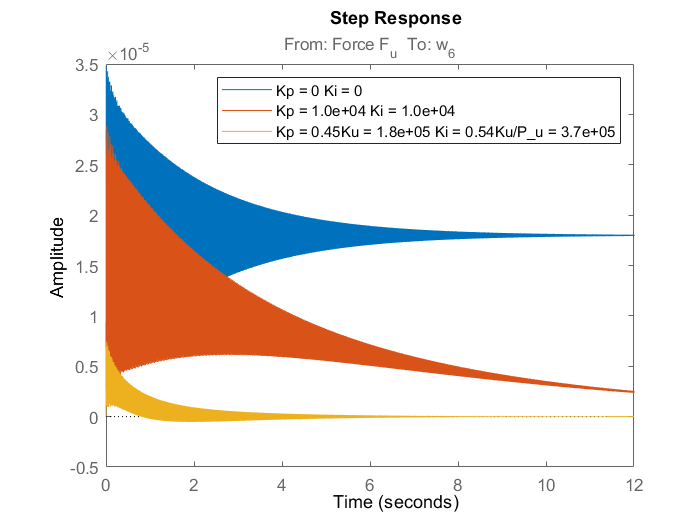

figure
step(G)
[~,time]=step(G);
for i=1:length(Ki)
hold on
step(G_fb_I(i))%,time)
end
xlim([0 12])
ylim([-0.5e-5 3.5e-5])
legend(legend_I)
if save_figure_var == 1
savefig('Figures/Step_G_crtl_I_var');
save_fig_pdf('Figures/Step_G_crtl_I_var');
end

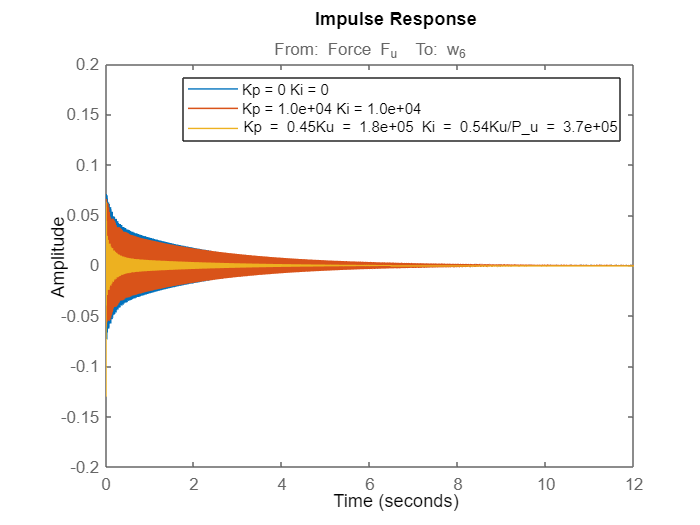

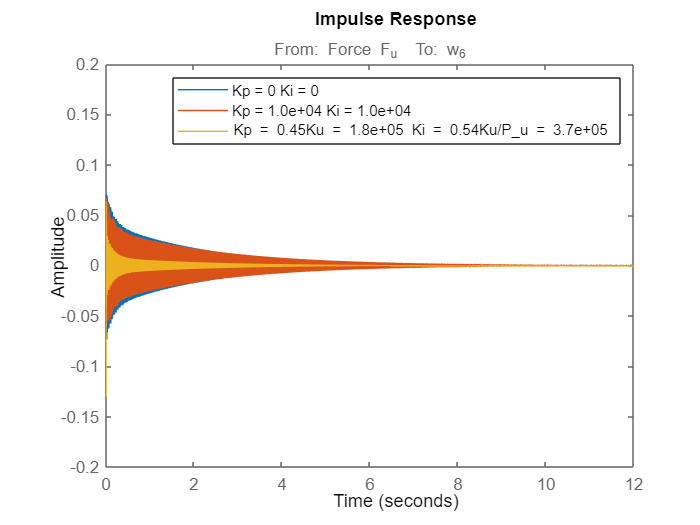


figure
impulse(G)
for i=1:length(Ki)
hold on
impulse(G_fb_I(i))
end
xlim([0 12])
ylim([-0.2 0.2])
legend(legend_I)

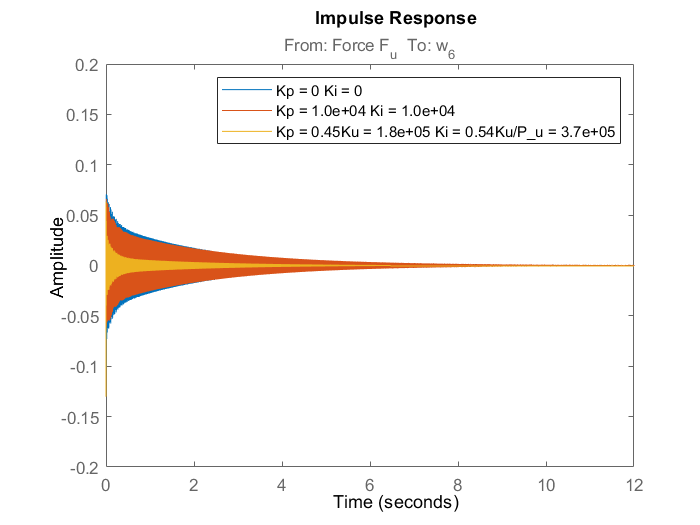

if save_figure_var == 1
    savefig('Figures/Impulse_G_crtl_I_var');
    save_fig_pdf('Figures/Impulse_G_crtl_I_var');
end

#### Derivative (D) Feedback :

The derivative monitors unusual variations of the error e by changing the output as a ”pre-act” or an ”anticipatory” controller. It is defined by Td = Kd/Kp the derivative action time. This action increases the phase of the controlled system and shifts the Nyquist plot away from the critical point, resulting in increased stability. The disadvantage is a decrease in static gain and static accuracy. It also induces high gain at high frequencies, which leads to noise amplification. The use of a pure derivative controller is practically impossible due to causality. Instead, a pseudo derivative controller [4] with a time constant Tf = 1/Fc is used. The Ziegler-Nichols method of tuning uses the period of the oscillation Pu produced at the ultimate sensitivity Ku, such as Kp = 0.6KuPu/8. This method can not be used to tune Kd since a filter is added. Instead, a graphical method to tune the derivative coefficient using root locus poles and zero variation with the gain Kd. To damp the system, the real part of the first three poles must be as negative as possible without inducing a positive real part of the higher frequency poles. In the example, the derivative controller is tuned to damp the oscillations of the first mode

Kp=[0 0]%[1e3 0.6*Kpu]

Kp =      0     0


Ki=[0 0]%[1e3 1.2*Kpu/Pu]

Ki =      0     0


Fc=5e4/2/pi

Fc = 7.9577e+03

Kd=[0.01 11]

Kd =     0.0100   11.0000


figure
rlocus(G*(1.*s*Fc/(s+Fc)))
xlim([-1600 10])
ylim([0 11e4])
hold on
i=2

i = 2

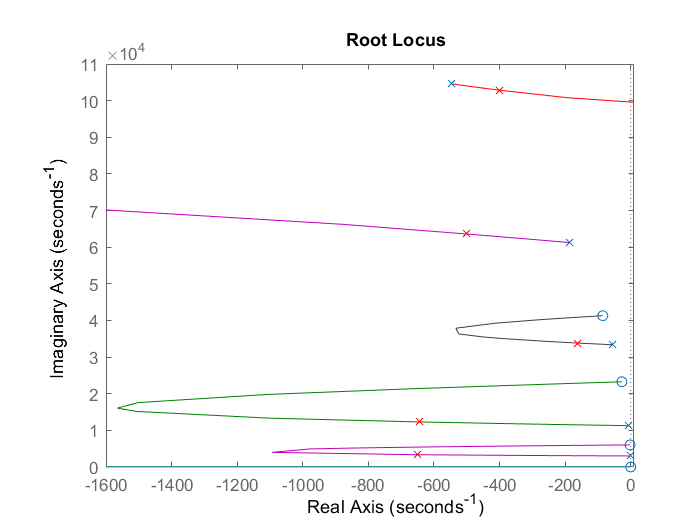

G_fb_D(i)=feedback(G, Kp(i)+Ki(i)/s+Kd(i)*s*Fc/(s+Fc),1,1); %*
plot(real(pole(G_fb_D(i))),imag(pole(G_fb_D(i))),'x','Color','red')
plot(real(pole(G)),imag(pole(G)),'x','Color',default_color(1,:))
if save_figure_var == 1
    savefig('Figures/PZ_G_crtl_D_var');
    save_fig_pdf('Figures/PZ_G_crtl_D_var');
end

Kd_legend=["Kd = " "Kd = " "Kd =  "]

Kd_legend = 1×3 string array
    "Kd = "    "Kd = "    "Kd =  "


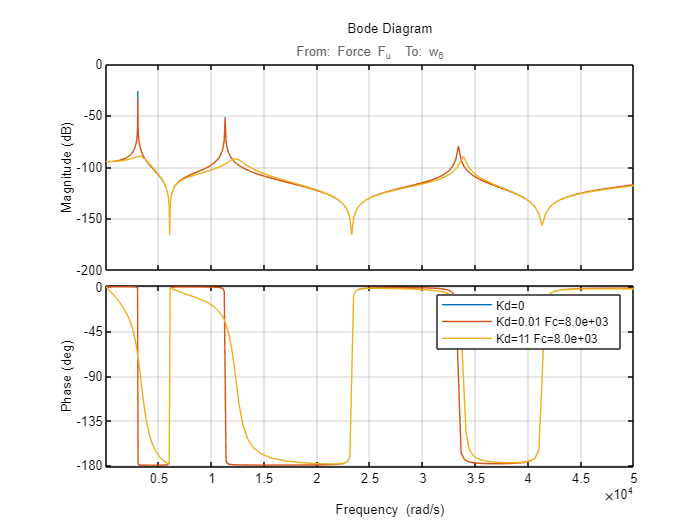

bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};
figure
bodeplot(G,bopt)
legend_D(1)="Kd="+num2str(0)+ " ";
for i=1:length(Kd)
G_fb_D(i)=feedback(G, Kp(i)+Ki(i)/s+Kd(i)*s*Fc/(s+Fc),1,1); %*
%G_fb_D(i)=feedback(G, Kp(i)+Ki(i)/s+Kd(i)*s,1,1); %*Fc/(s+Fc)
hold on
bodeplot(G_fb_D(i),bopt)
%legend_P(i+1)=Kp_legend(i+1)+num2str(Kp(i), '%.1e')+ " ";
%legend_I(i+1)=Ki_legend(i+1)+num2str(Ki(i), '%.1e')+ " ";
legend_D(i+1)="Kd="+num2str(Kd(i))+" Fc="+num2str(Fc, '%.1e');
end
legend(legend_D)

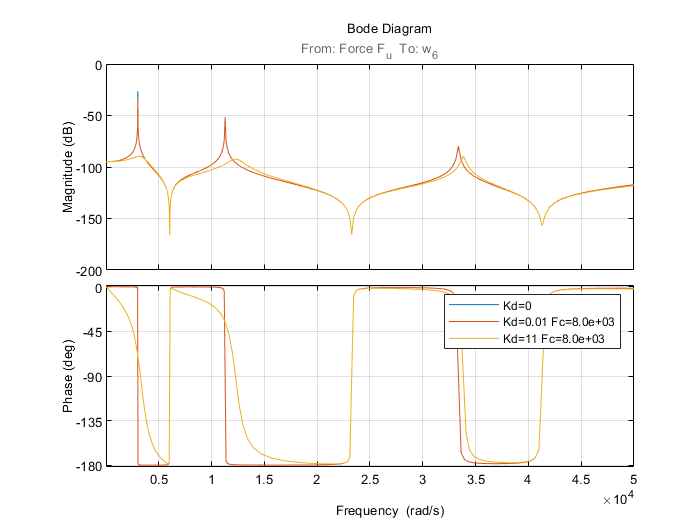

if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_D_var');
    save_fig_pdf('Figures/Bode_G_crtl_D_var');
end

%bopt.XLim={[1 8e4]};
figure
margin(G)
hold on
%legend_I(1)="Ki = "+ 0 + " ";
for i=1:length(Ki)
margin(G*(Kd(i).*s*Fc/(s+Fc)+Kp(i)+Ki(i)/s),bopt)
[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*(Kd(i).*s*Fc/(s+Fc)+Kp(i)+Ki(i)/s));
%[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*(Kd(i).*s+Kp(i)+Ki(i)/s));
%legend_I(i+1)=Ki_legend(i+1)+num2str(Ki(i), '%.1e')+ " ";
%text_margin(i,:)=
("Gm = "+ num2str(20*log10(Gm1(i)), '%.1e') + "dB  (at "+ num2str(Wcg1(i), '%.1e') +"rad/s),  Pm = "+ num2str(Pm1(i)) + "deg (at "+ num2str(Wcp1(i), '%.1e') +" rad/s)")
end

ans = "Gm = 6.9e+01dB  (at 9.9e+04rad/s),  Pm = 117.2888deg (at 3.0e+03 rad/s)"

ans = "Gm = 8.3e+00dB  (at 9.9e+04rad/s),  Pm = 11.349deg (at 6.4e+04 rad/s)"

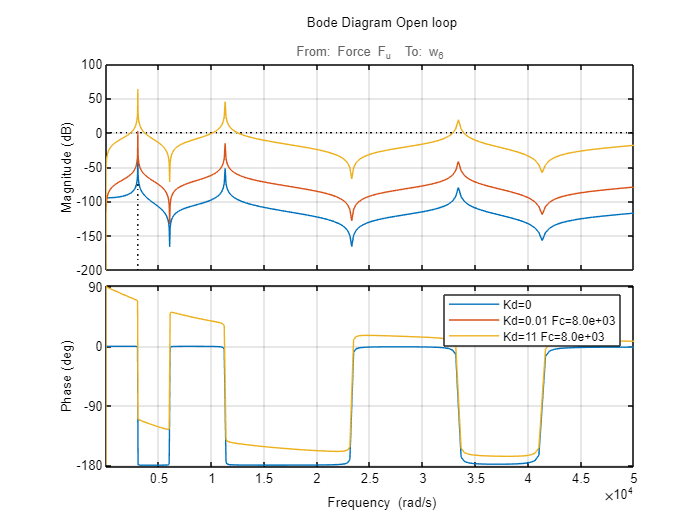


legend(legend_D)
% Create title
title({'Bode Diagram Open loop'},...
    'HitTest','off',...
    'Units','pixels',...
    'HorizontalAlignment','center',...
    'FontSize',8);

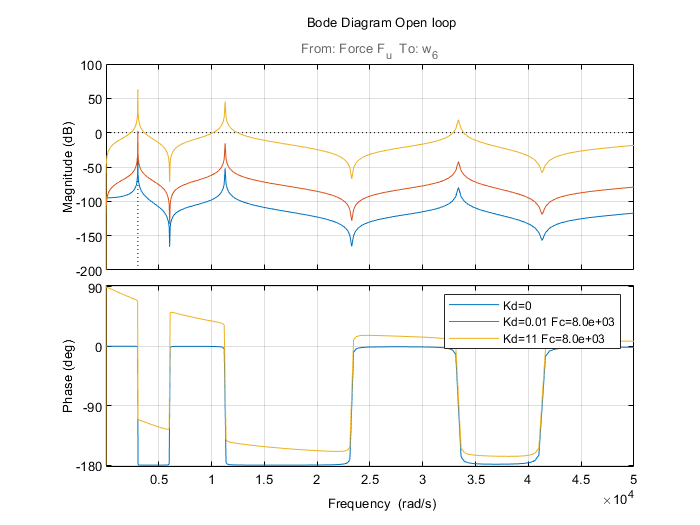

if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_D_var_margin')
    save_fig_pdf('Figures/Bode_G_crtl_D_var_margin')
end

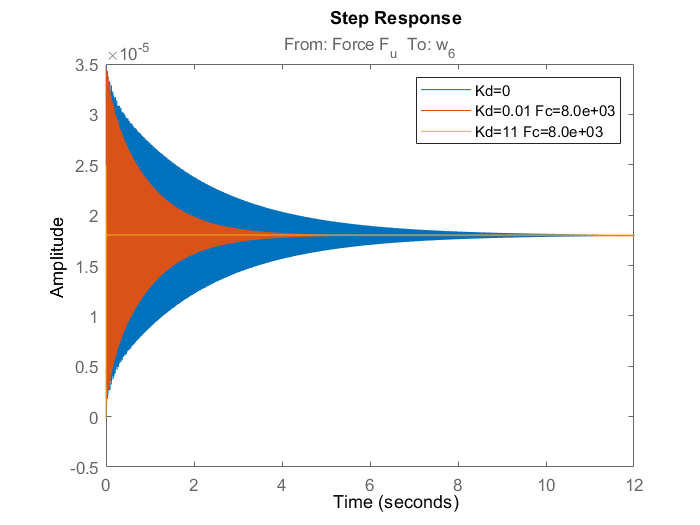

figure
step(G)
[~,time]=step(G);
hold on
for i=1:length(Kd)
step(G_fb_D(i))%,time)
end
legend(legend_D)
xlim([0 12])
if save_figure_var == 1
    savefig('Figures/Step_G_crtl_D_var');
    save_fig_pdf('Figures/Step_G_crtl_D_var');
end



figure
impulse(G)
hold on
for i=1:length(Kd)
impulse(G_fb_D(i))
legend(legend_D)
end

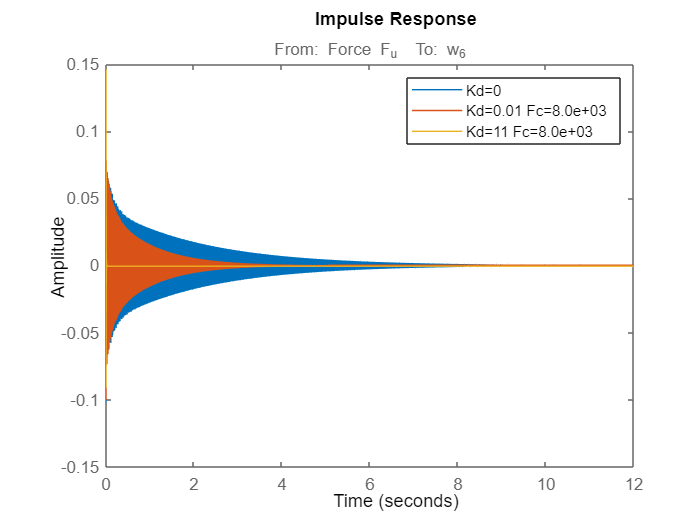

xlim([0 12])

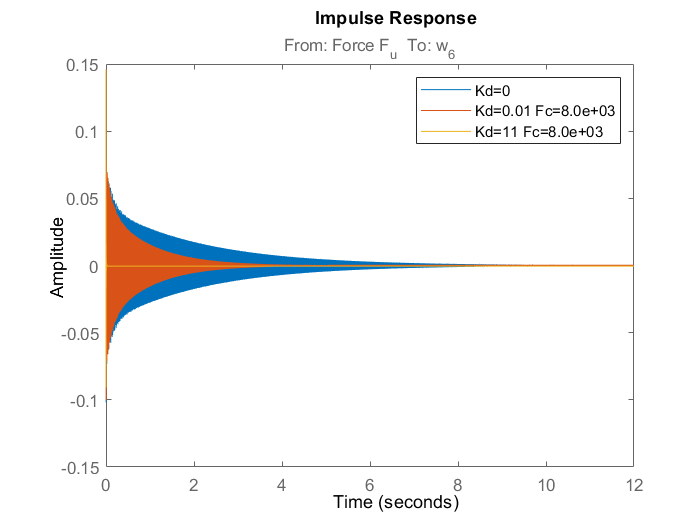

if save_figure_var == 1
    savefig('Figures/Impulse_G_crtl_D_var');
    save_fig_pdf('Figures/Impulse_G_crtl_D_var');
end

### Lead-Lag Compensator 

Lead and lag compensators are designed to act on local correction so can be specific and adapted to the case. Analytically designed in 1976 by Wakeland [5] for the phase-lead compensation and refined by Mitchell [6] for the phase-lag compensation, the formulation is written as follows : 

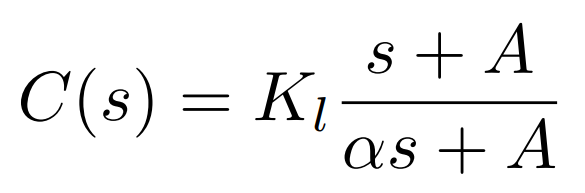

Where Kl is the gain, A is the frequency in [rad.sec−1 ], α < 1 defines a lead compensator and α > 1 defines a lag compensator.

Kl=[20 50 1000*100]

Kl =           20          50      100000


A=[2.5e3 2.4e3 1.2e3] %rad/sec

A =         2500        2400        1200


B=[A(1) A(2) 6.1e3]

B =         2500        2400        6100


alpha= [30 0.5 1]

alpha =    30.0000    0.5000    1.0000


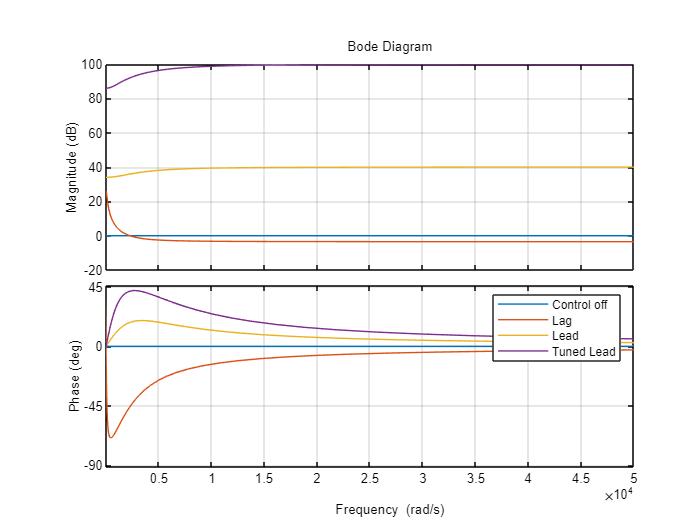



for i=1:length(Kl)
Crtl_law(i)=Kl(i)*(A(i)+s)/(B(i)+alpha(i)*s);
end

legend_l=["Control off" "Lag" "Lead" "Tuned Lead"];


bopt.XLim={[1 5e4]};

figure
bode(s/s,bopt)
for i=1:length(Kl)
    hold on
    bode(Crtl_law(i),bopt)
end
legend(legend_l)

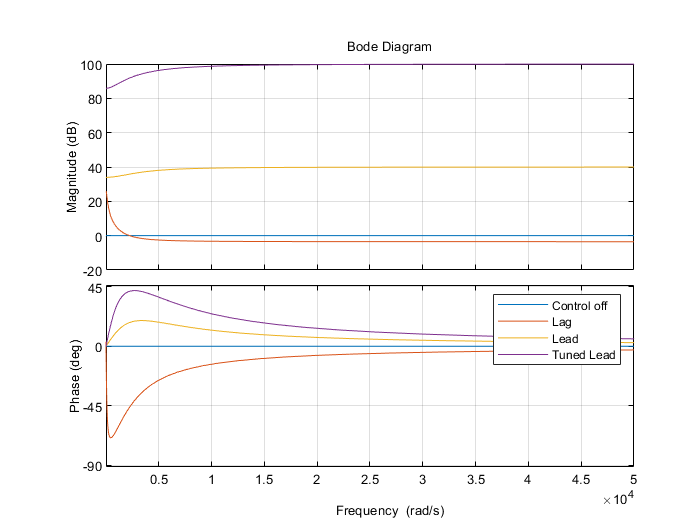


if save_figure_var == 1
    savefig('Figures/Bode_lead_crtl');
    save_fig_pdf('Figures/Bode_lead_crtl');
end

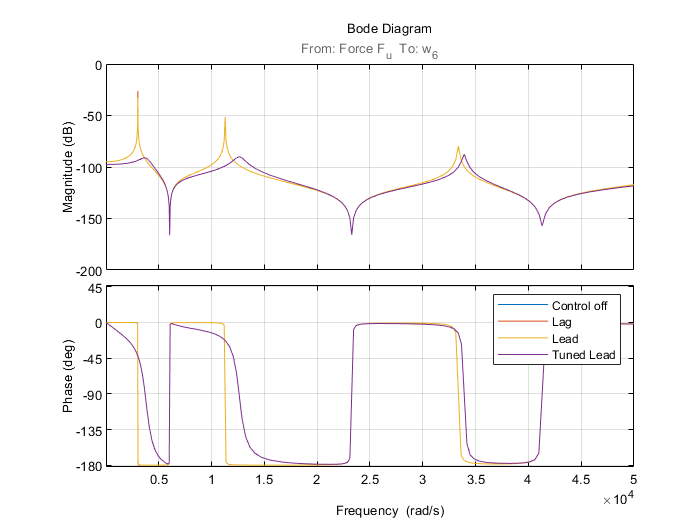


bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};
figure
bodeplot(G,bopt)
legend_D(1)="Kl="+num2str(0)+ " ";

for i=1:length(Kl)
G_fb_l(i)=feedback(G, Crtl_law(i),1,1); %*
hold on
bodeplot(G_fb_l(i),bopt)
end
legend(legend_l)
if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_Lead_var');
    save_fig_pdf('Figures/Bode_G_crtl_Lead_var');
end

bopt.XLim={[1 1.2e5]};
figure
margin(G)
hold on
%legend_I(1)="Ki = "+ 0 + " ";
for i=1:length(Kl)
margin(G*Crtl_law(i),bopt)
[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*Crtl_law(i));
%[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*(Kd(i).*s+Kp(i)+Ki(i)/s));
%legend_I(i+1)=Ki_legend(i+1)+num2str(Ki(i), '%.1e')+ " ";
%text_margin(i,:)=
("Gm = "+ num2str(20*log10(Gm1(i)), '%.1e') + "dB  (at "+ num2str(Wcg1(i), '%.1e') +"rad/s),  Pm = "+ num2str(Pm1(i)) + "deg (at "+ num2str(Wcp1(i), '%.1e') +" rad/s)")
end

ans = "Gm = 3.2e+01dB  (at 3.0e+03rad/s),  Pm = Infdeg (at NaN rad/s)"

ans = "Gm = 7.2e+01dB  (at 9.2e+04rad/s),  Pm = 37.312deg (at 3.0e+03 rad/s)"

ans = "Gm = 9.4e+00dB  (at 9.7e+04rad/s),  Pm = 7.9608deg (at 6.4e+04 rad/s)"

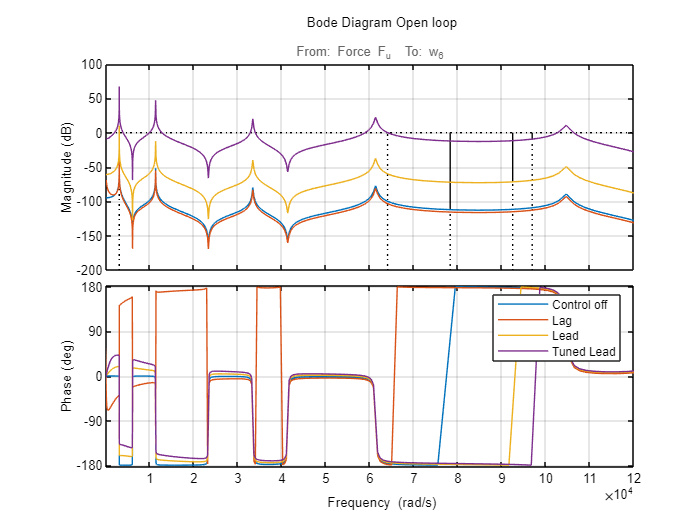

legend(legend_l)
% Create title
title({'Bode Diagram Open loop'},...
    'HitTest','off',...
    'Units','pixels',...
    'HorizontalAlignment','center',...
    'FontSize',8);

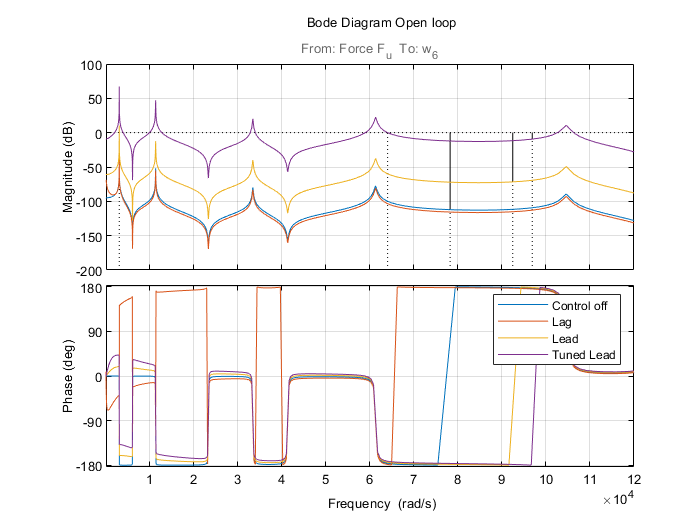


if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_Lead_var_margin')
    save_fig_pdf('Figures/Bode_G_crtl_Lead_var_margin')
end

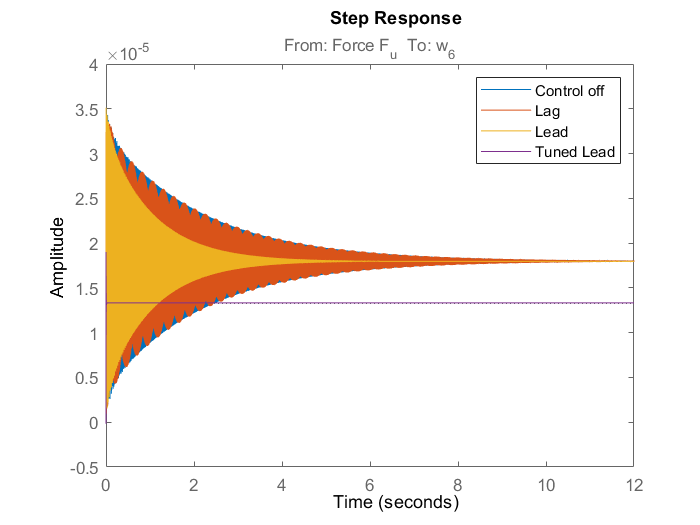

figure
step(G)
[~,time]=step(G);
hold on
for i=1:length(Kl)
step(G_fb_l(i))%,time)
end
legend(legend_l)
xlim([0 12])
if save_figure_var == 1
    savefig('Figures/Step_G_crtl_Lead_var');
    save_fig_pdf('Figures/Step_G_crtl_Lead_var');
end



figure
impulse(G)
hold on
for i=1:length(Kl)
impulse(G_fb_l(i))
legend(legend_l)
end

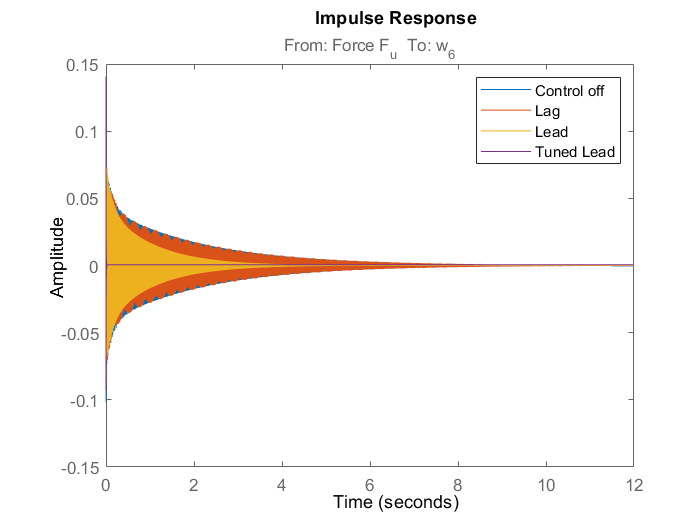

xlim([0 12])
if save_figure_var == 1
    savefig('Figures/Impulse_G_crtl_Lead_var');
    save_fig_pdf('Figures/Impulse_G_crtl_Lead_var');
end

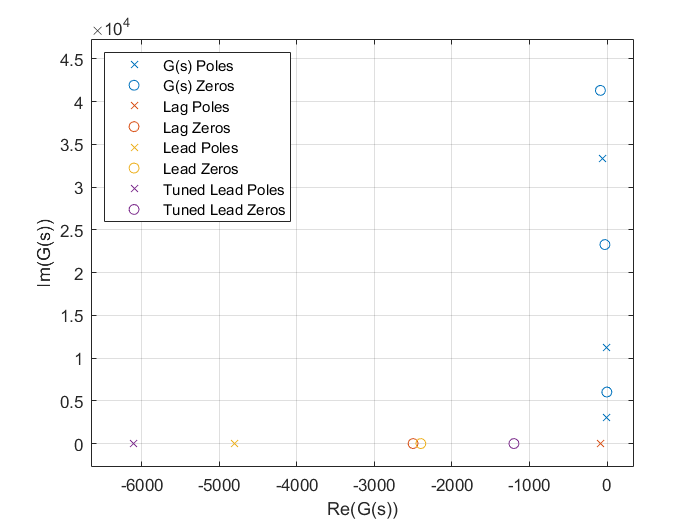


figure
plot(real(pole(G)),imag(pole(G)),'x','Color',default_color(1,:))
hold on
plot(real(zero(G)),imag(zero(G)),'o','Color',default_color(1,:))
for i=1:length(Kl)
    plot(real(pole(Crtl_law(i))),imag(pole(Crtl_law(i))),'x','Color',default_color(i+1,:))
    plot(real(zero(Crtl_law(i))),imag(zero(Crtl_law(i))),'o','Color',default_color(i+1,:))
end
xlim([-7e3 0])
ylim([-50 5e4])
xlabel('Re(G(s))')
ylabel('Im(G(s))')
legend('G(s) Poles','G(s) Zeros','Lag Poles','Lag Zeros','Lead Poles','Lead Zeros','Tuned Lead Poles','Tuned Lead Zeros','Location','northwest')
grid on
xlim([-6652 348])
ylim([-2740 47310])

Comments: 

The lead controller adds phase to the loop transfer function and improves the phase margin. The added phase is maximum and is equal to ϕ(ωm) = arcsin( α−1/1+α ) at the pulsation ωm = A/√α . The controller pole and zero are designed so that the crossover frequency is between the two values. 

The lag controller adds negative phase to the loop transfer function, which can lead to stability problems. The aim is to exploit locally the integrator behavior of the controller and to increase the static accuracy. The maximum loss phase is equal to ϕ(ωm) = arcsin( 1−α/1+α ) at the pulsation ωm = A /√α . It is placed at low frequencies such as the poles and the zeros are below the crossover frequency of the uncontrolled system.

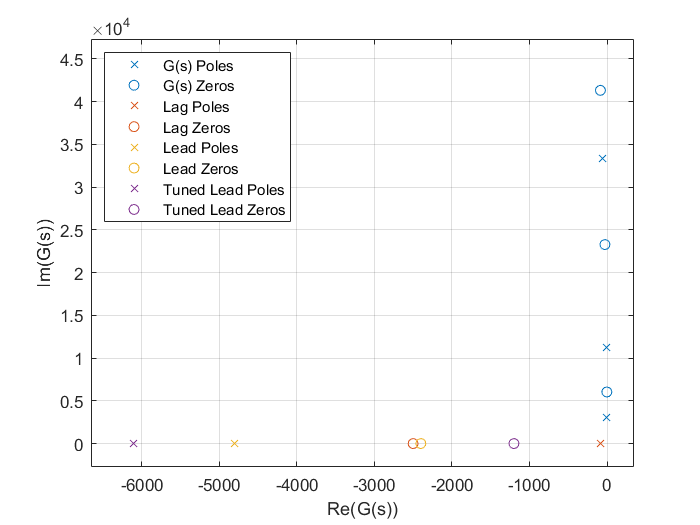

if save_figure_var == 1
    savefig('Figures/PZ_G_crtl_Lead_var');
    save_fig_pdf('Figures/PZ_G_crtl_Lead_var');
end

### Positive Position Feedback (PPF)

Proposed by Goh and Caughey [7], the Positive Position Feedback (PPF) controller is a second-order filter such as :

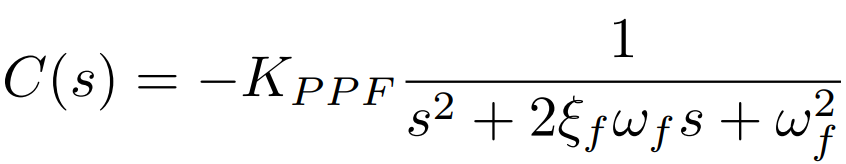

Where K_PPF is the gain, ωf is the filter frequency adapted to the target mode in [rad.sec−1 ] and ξf is the damping ratio. It ensures control of low frequency modes while not destabilizing higher frequency modes.

To tune the PPF controller, first set ωf to the mode frequency to be controlled, then set ξf usually between 0.5 and 0.7, and adjust the gain Kppf with the root locus.

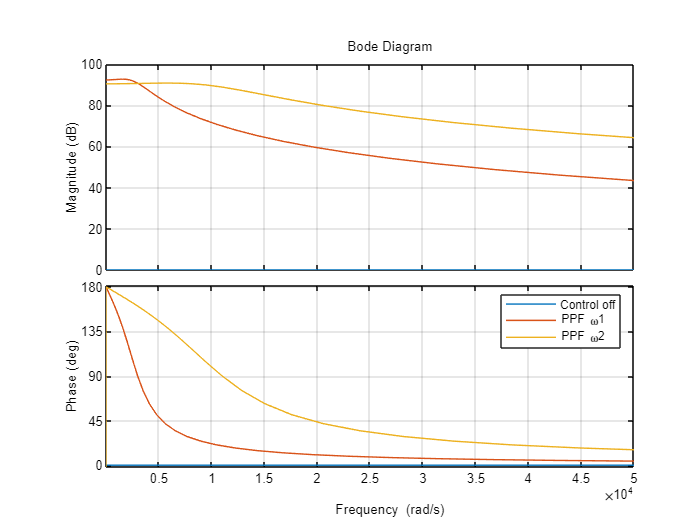

K_PPF=[100*3.7e9 100*4e10];
Xi_f=[0.6 0.6];
omega_f=[3000 11000];


for i=1:length(K_PPF)
Crtl_law(i)=-K_PPF(i)/(s^2+2*Xi_f(i)*omega_f(i)*s+omega_f(i)^2);
end

legend_PPF=["Control off" "PPF \omega1" "PPF \omega2"];


bopt.XLim={[1 5e4]};

figure
bode(s/s,bopt)
for i=1:length(K_PPF)
    hold on
    bode(Crtl_law(i),bopt)
end
legend(legend_PPF)

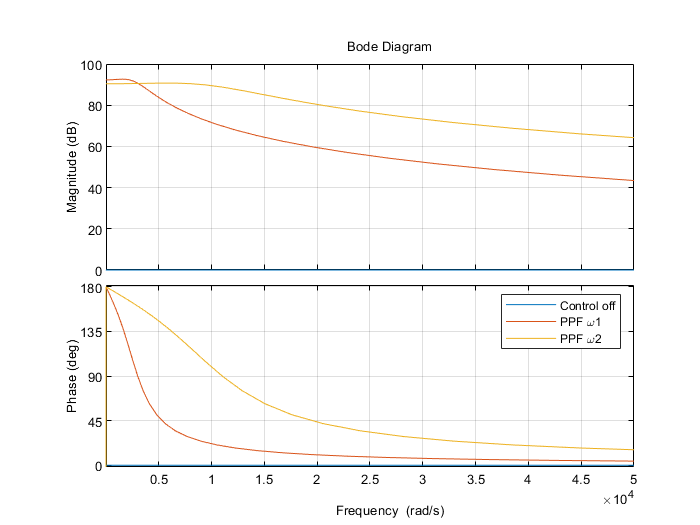


if save_figure_var == 1
    savefig('Figures/Bode_ppf_crtl');
    save_fig_pdf('Figures/Bode_ppf_crtl');
end

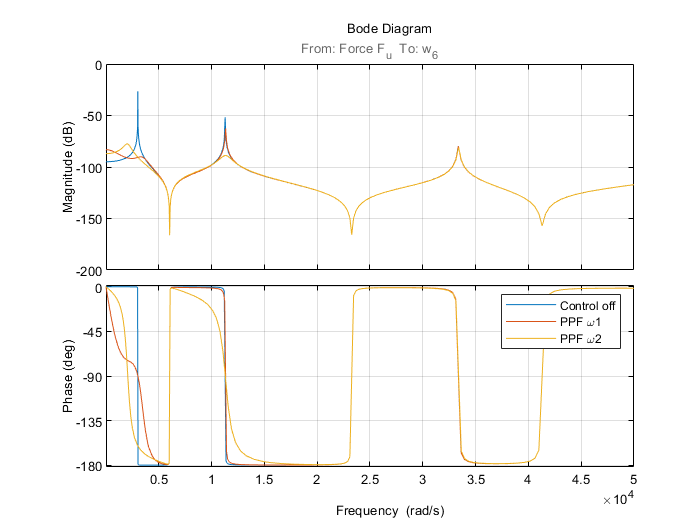


bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};
figure
bodeplot(G,bopt)

for i=1:length(K_PPF)
G_fb_l(i)=feedback(G, Crtl_law(i),1,1); %*
hold on
bodeplot(G_fb_l(i),bopt)
end
legend(legend_PPF)
if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_ppf_var');
    save_fig_pdf('Figures/Bode_G_crtl_ppf_var');
end


bopt.XLim={[1 1.2e5]};
figure
margin(G)
hold on
for i=1:length(K_PPF)
margin(G*Crtl_law(i),bopt)
[Gm1(i), Pm1(i), Wcg1(i), Wcp1(i)]=margin(G*Crtl_law(i));
("Gm = "+ num2str(20*log10(Gm1(i)), '%.1e') + "dB  (at "+ num2str(Wcg1(i), '%.1e') +"rad/s),  Pm = "+ num2str(Pm1(i)) + "deg (at "+ num2str(Wcp1(i), '%.1e') +" rad/s)")
end

ans = "Gm = 2.6e+00dB  (at 0.0e+00rad/s),  Pm = 26.4744deg (at 1.1e+04 rad/s)"

ans = "Gm = 4.5e+00dB  (at 0.0e+00rad/s),  Pm = -12.9141deg (at 2.0e+03 rad/s)"

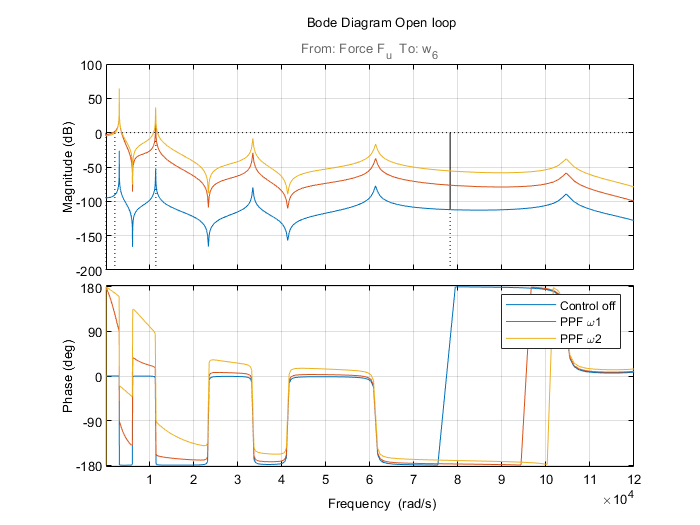

legend(legend_PPF)
% Create title
title({'Bode Diagram Open loop'},...
    'HitTest','off',...
    'Units','pixels',...
    'HorizontalAlignment','center',...
    'FontSize',8);

if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_ppf_var_margin')
    save_fig_pdf('Figures/Bode_G_crtl_ppf_var_margin')
end

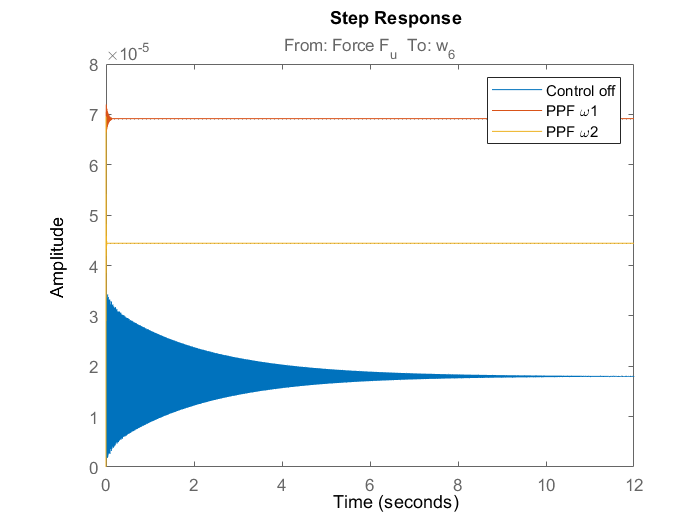


figure
step(G)
[~,time]=step(G);
hold on
for i=1:length(K_PPF)
step(G_fb_l(i))%,time)
end
legend(legend_PPF)
xlim([0 12])
if save_figure_var == 1
    savefig('Figures/Step_G_crtl_ppf_var');
    save_fig_pdf('Figures/Step_G_crtl_ppf_var');
end



figure
impulse(G)
hold on
for i=1:length(K_PPF)
impulse(G_fb_l(i))
legend(legend_PPF)
end

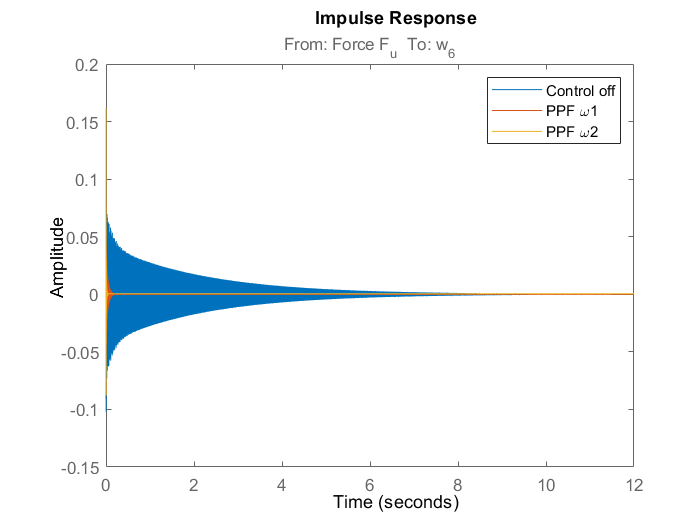

xlim([0 12])
if save_figure_var == 1
    savefig('Figures/Impulse_G_crtl_ppf_var');
    save_fig_pdf('Figures/Impulse_G_crtl_ppf_var');
end

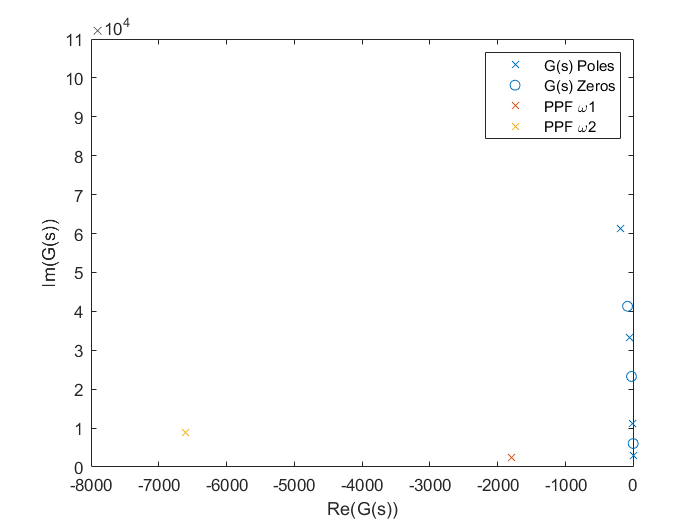


figure
plot(real(pole(G)),imag(pole(G)),'x','Color',default_color(1,:))
hold on
plot(real(zero(G)),imag(zero(G)),'o','Color',default_color(1,:))
for i=1:length(K_PPF)
    plot(real(pole(Crtl_law(i))),imag(pole(Crtl_law(i))),'x','Color',default_color(i+1,:))
    plot(real(zero(Crtl_law(i))),imag(zero(Crtl_law(i))),'o','Color',default_color(i+1,:))
end

xlim([-8000 10])
ylim([0 11e4])
xlabel('Re(G(s))')
ylabel('Im(G(s))')
legend('G(s) Poles','G(s) Zeros','PPF \omega1','PPF \omega2')

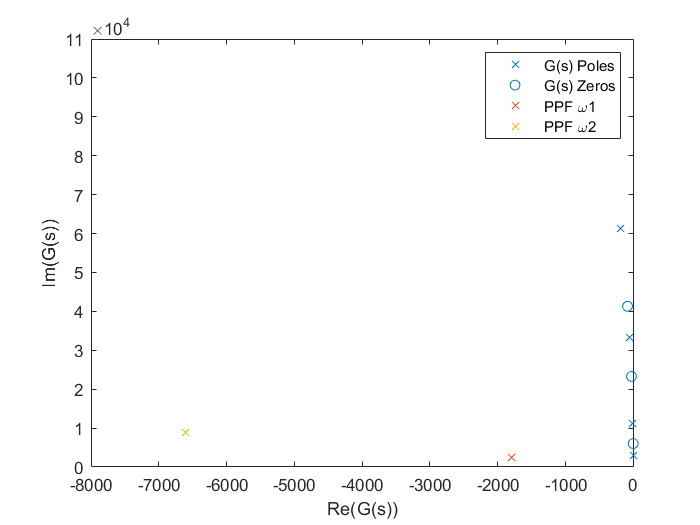

if save_figure_var == 1
    savefig('Figures/PZ_G_crtl_ppf_var');
    save_fig_pdf('Figures/PZ_G_crtl_ppf_var');
end

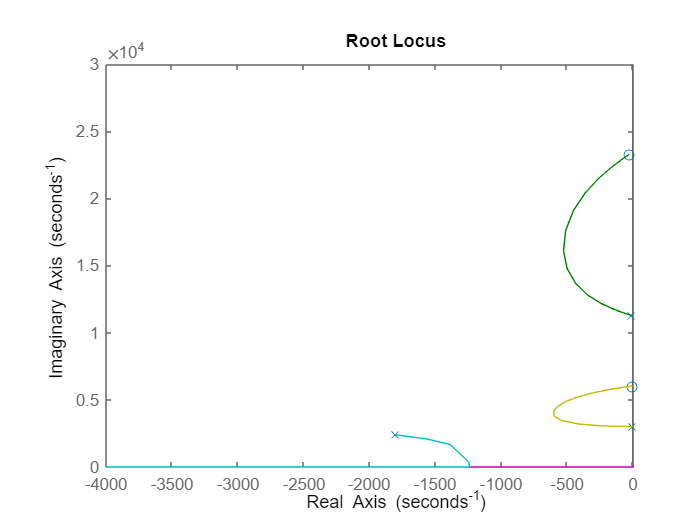


figure
rlocus(G*Crtl_law(1))
xlim([-4000 10])
ylim([0 3e4])

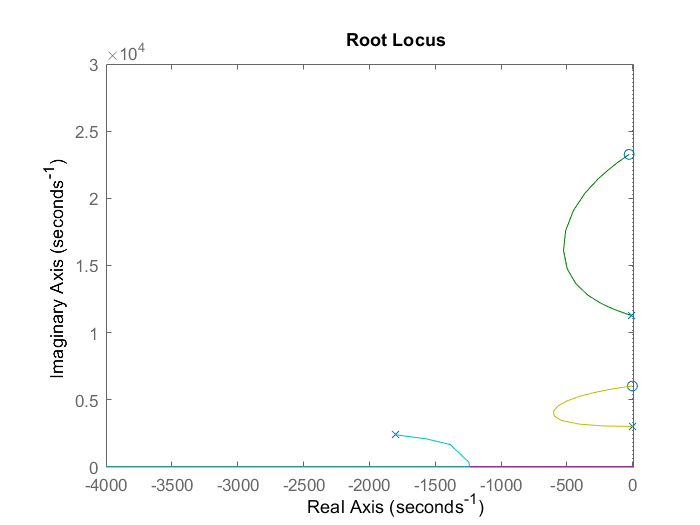

if save_figure_var == 1
    savefig('Figures/rlocus_G_crtl_ppf_1');
    save_fig_pdf('Figures/rlocus_G_crtl_ppf_1');
end

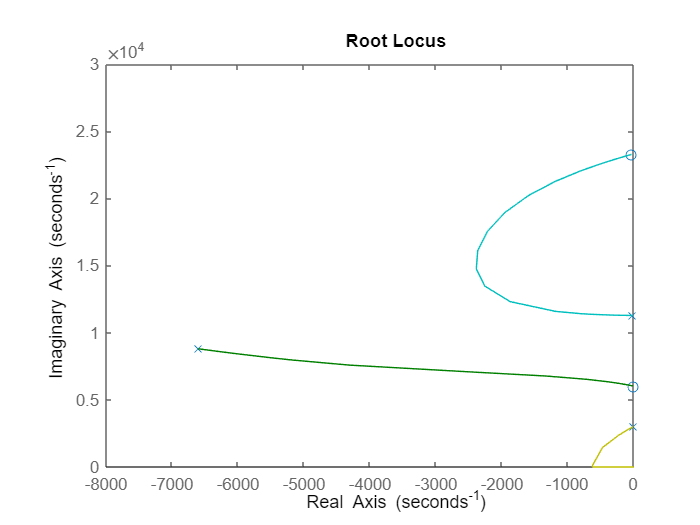


figure
rlocus(G*Crtl_law(2))
xlim([-8000 10])
ylim([0 3e4])

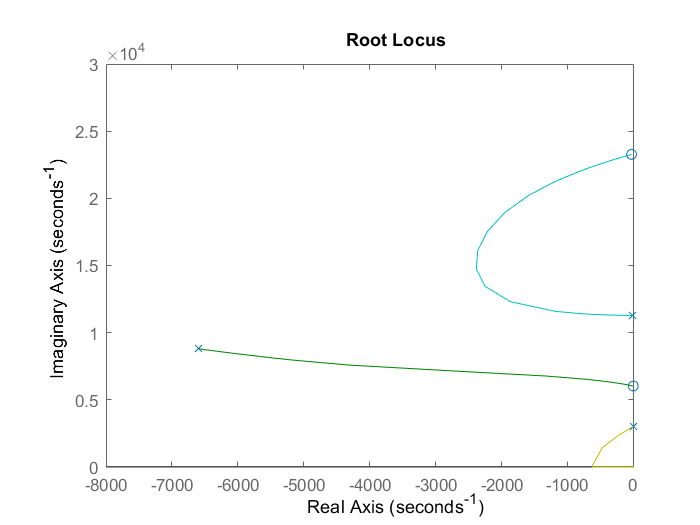

if save_figure_var == 1
    savefig('Figures/rlocus_G_crtl_ppf_2');
    save_fig_pdf('Figures/rlocus_G_crtl_ppf_2');
end

### Compare all control laws

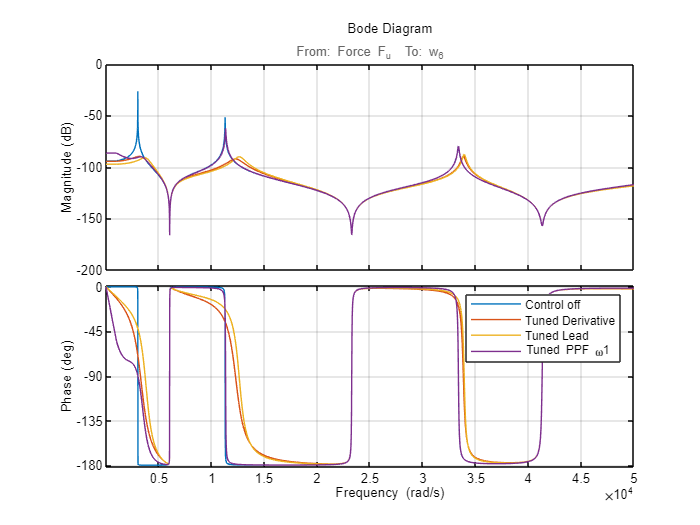

interval_plot=[1000:0.01:5000];
bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[2e3 4e3]};
%bopt.XLim={[3000 4500]};

interval_plot=[1000:0.1:50000];
bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};

figure
hold on
bodeplot(G,interval_plot,bopt)
bodeplot(G_fb_D(2),interval_plot,bopt)

Crtl_law(1)=Kl(3)*(A(3)+s)/(B(3)+alpha(end)*s);
Crtl_law(2)=-K_PPF(1)/(s^2+2*Xi_f(1)*omega_f(1)*s+omega_f(1)^2);

for i=1:2
G_fb_l(i)=feedback(G, Crtl_law(i),1,1); %*
hold on
bodeplot(G_fb_l(i),interval_plot,bopt)
end
legend('Control off', 'Tuned Derivative', 'Tuned Lead','Tuned PPF \omega1')

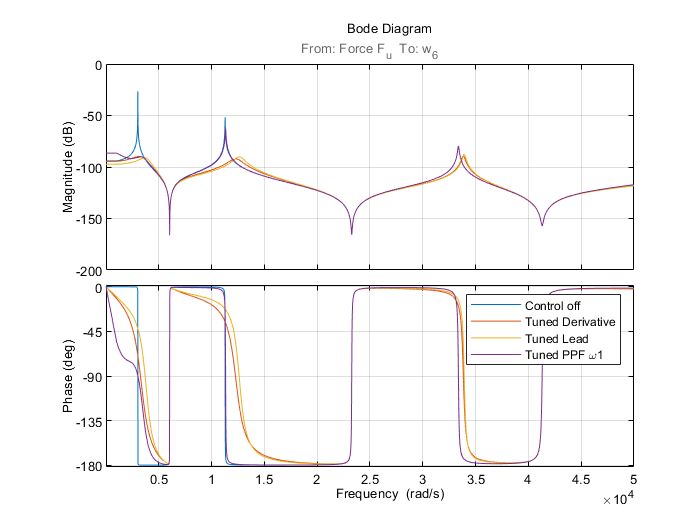


if save_figure_var == 1
    savefig('Figures/Bode_G_crtl_diff_act_crtl_var');
    save_fig_pdf('Figures/Bode_G_crtl_diff_act_crtl_var');
end

## Bibliography

[1] H. Nyquist. “Regeneration Theory”. In : Bell System Technical Journal 11.1 (jan. 1932), p. 126- 147. issn : 0005-8580. doi : 10.1002/j.1538-7305.1932.tb02344.x. 

[2] Rakesh P. Borase et al. “A review of PID control, tuning methods and applications”. In : Inter�national Journal of Dynamics and Control 9.2 (juill. 2020), p. 818-827. doi : 10.1007/s40435- 020-00665-4.

[3] J. G. Ziegler et N. B. Nichols. “Optimum Settings for Automatic Controllers”. In : Transactions of the American Society of Mechanical Engineers 64.8 (d´ec. 2022), p. 759-765. issn : 0097-6822. doi : 10.1115/1.4019264.

[4] Osita D. I. Nwokah. “Pseudo-Derivative Feedback Control”. In : 1987 American Control Confe�rence. T. 134. Juin 1987, p. 1811-1814. doi : 10 . 23919 / ACC . 1987 . 4789606. url : https : / / ieeexplore.ieee.org/document/4789606 (visit´e le 02/08/2024). 

[5] W. Wakeland. “Bode compensator design”. In : IEEE Transactions on Automatic Control 21.5 (oct. 1976), p. 771-773. issn : 0018-9286. doi : 10.1109/tac.1976.1101362.

[6] J. Mitchell. “Comments on “Bode compensator design””. In : IEEE Transactions on Automatic Control 22.5 (oct. 1977), p. 869-870. issn : 1558-2523. doi : 10.1109/tac.1977.1101590

[7] C. J. GOH et T. K. CAUGHEY. “On the stability problem caused by finite actuator dynamics in the collocated control of large space structures”. In : International Journal of Control 41.3 (mars 1985), p. 787-802. issn : 0020-7179. doi : 10 . 1080 / 0020718508961163. url : https : //doi.org/10.1080/0020718508961163 (visit´e le 05/08/2024).